# Nyquist diagrams

s = tf('s');

## Intrinsic stability

This system is always closed-loop stable, regardless of the gain.

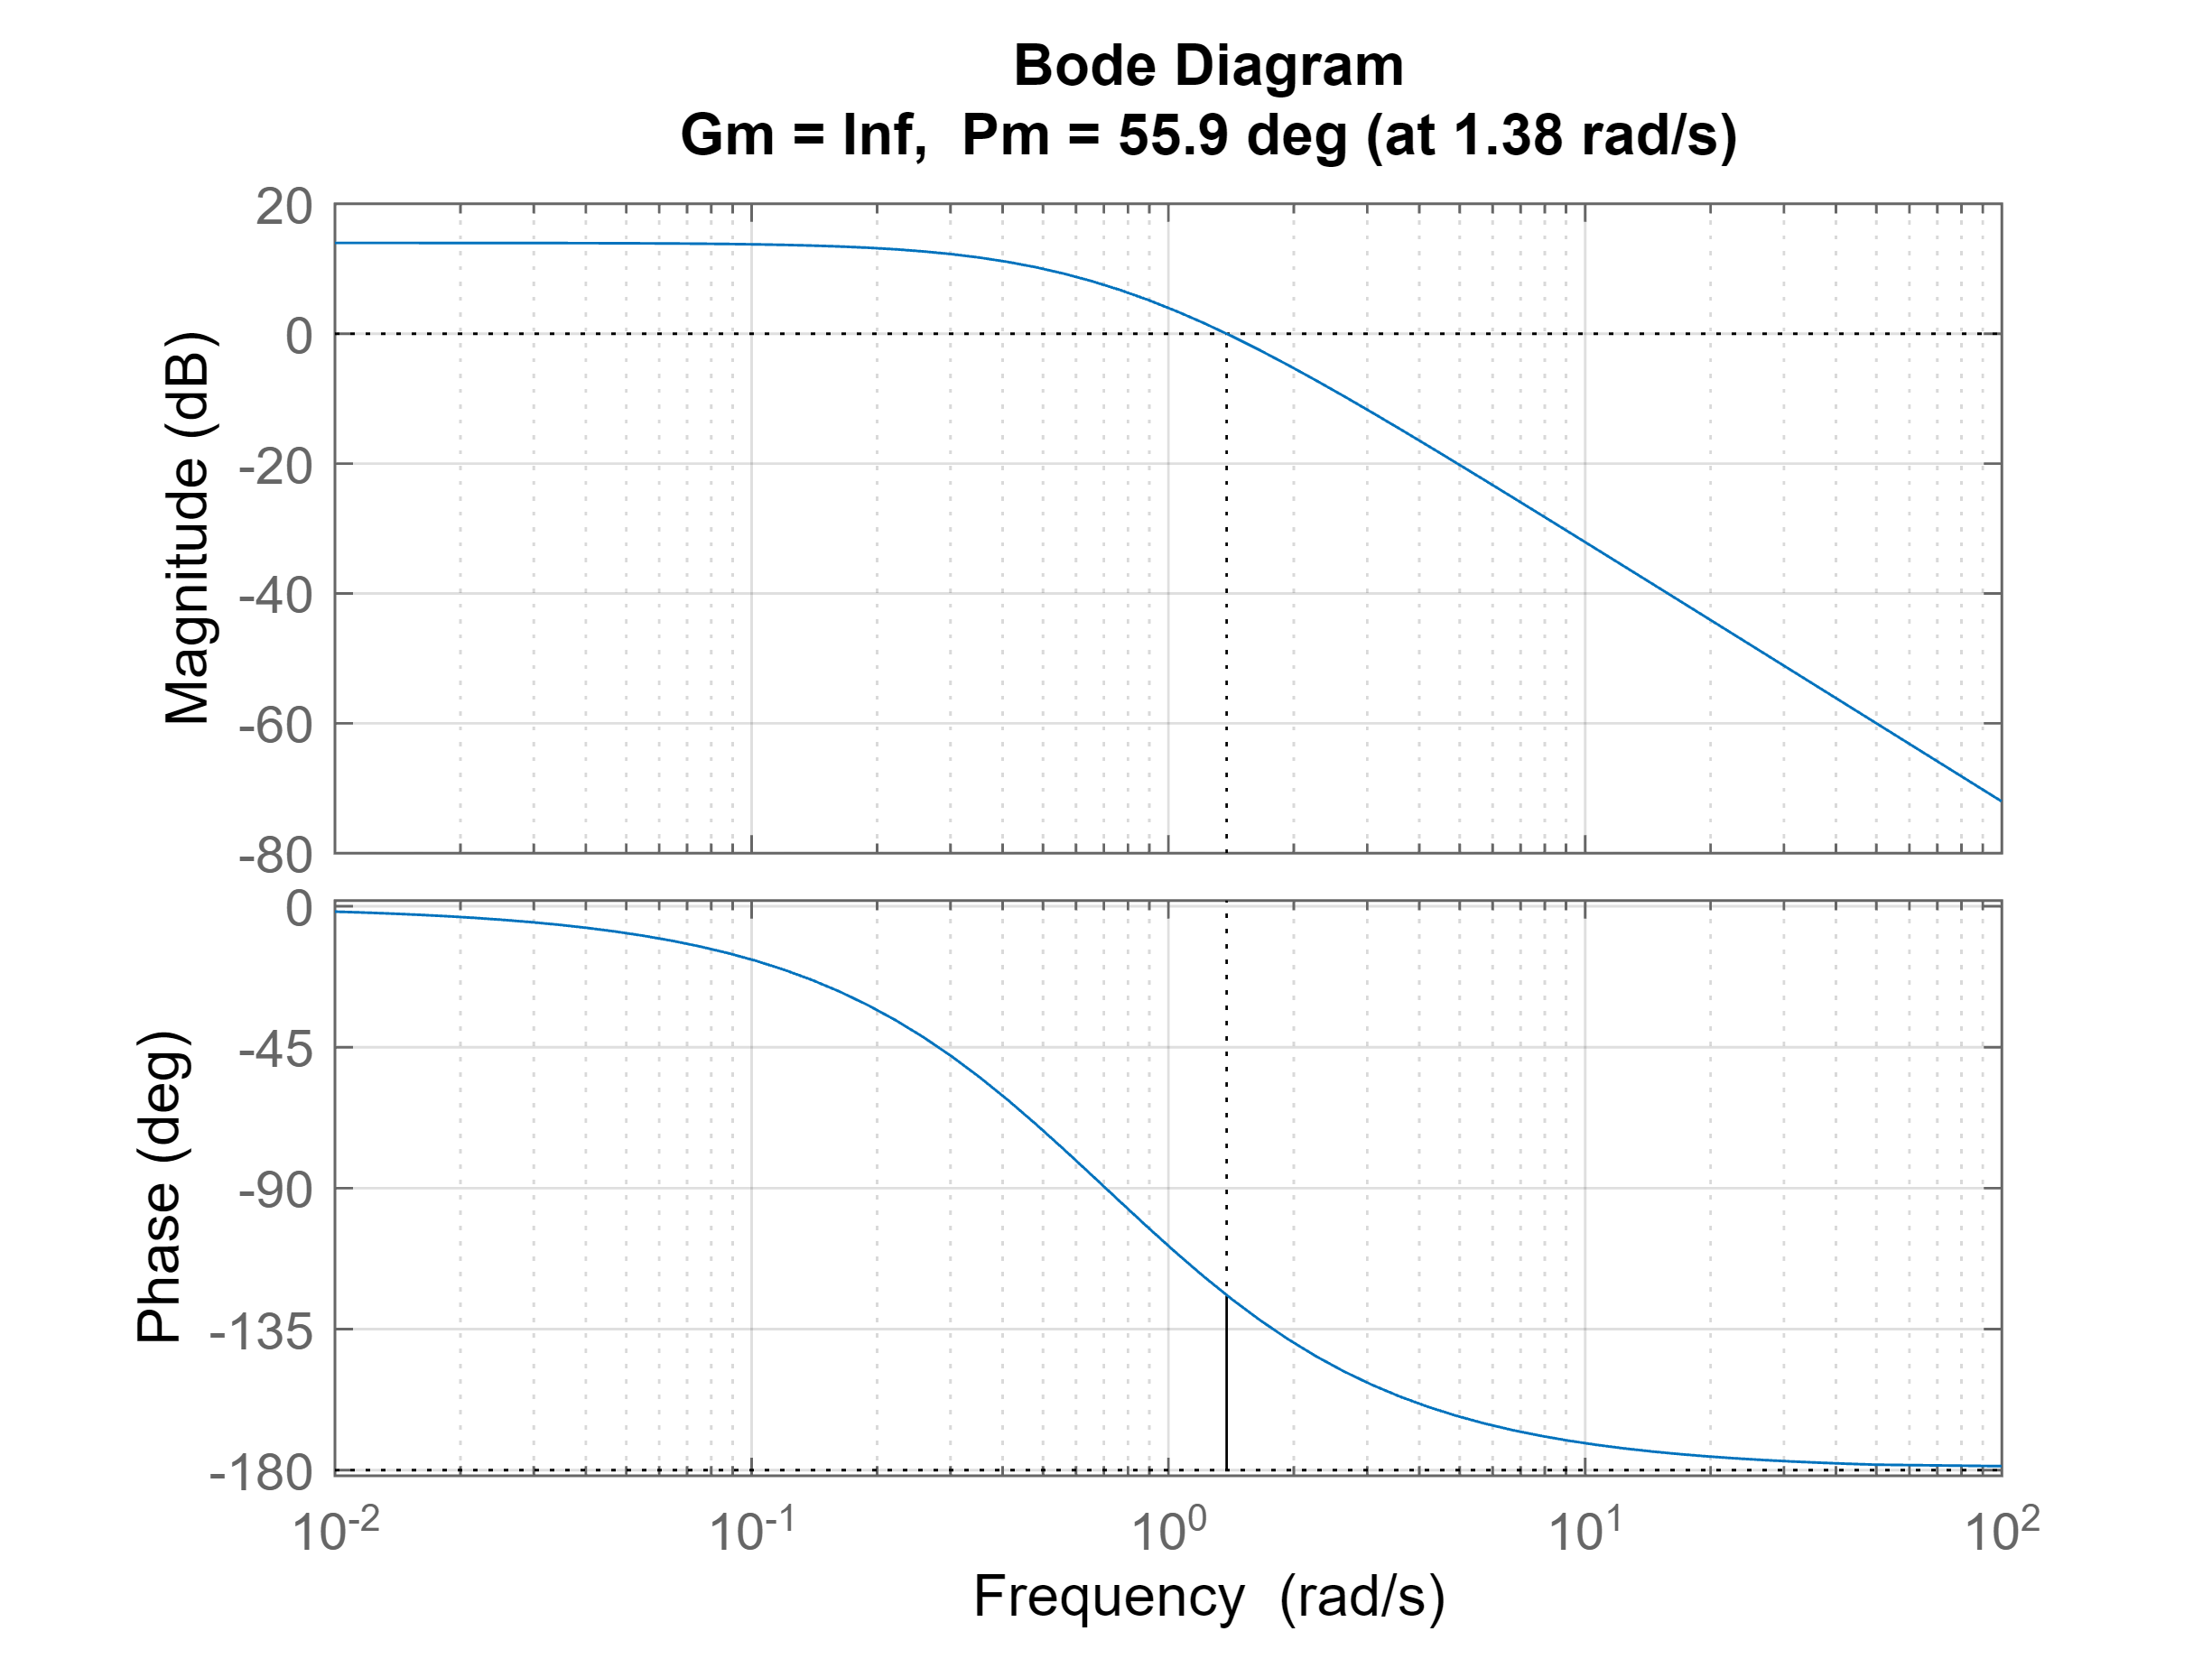

T1 = 1;
T2 = 2;
k = 5;

L = k/((1+s*T1)*(1+s*T2));

figure
margin(L), grid on

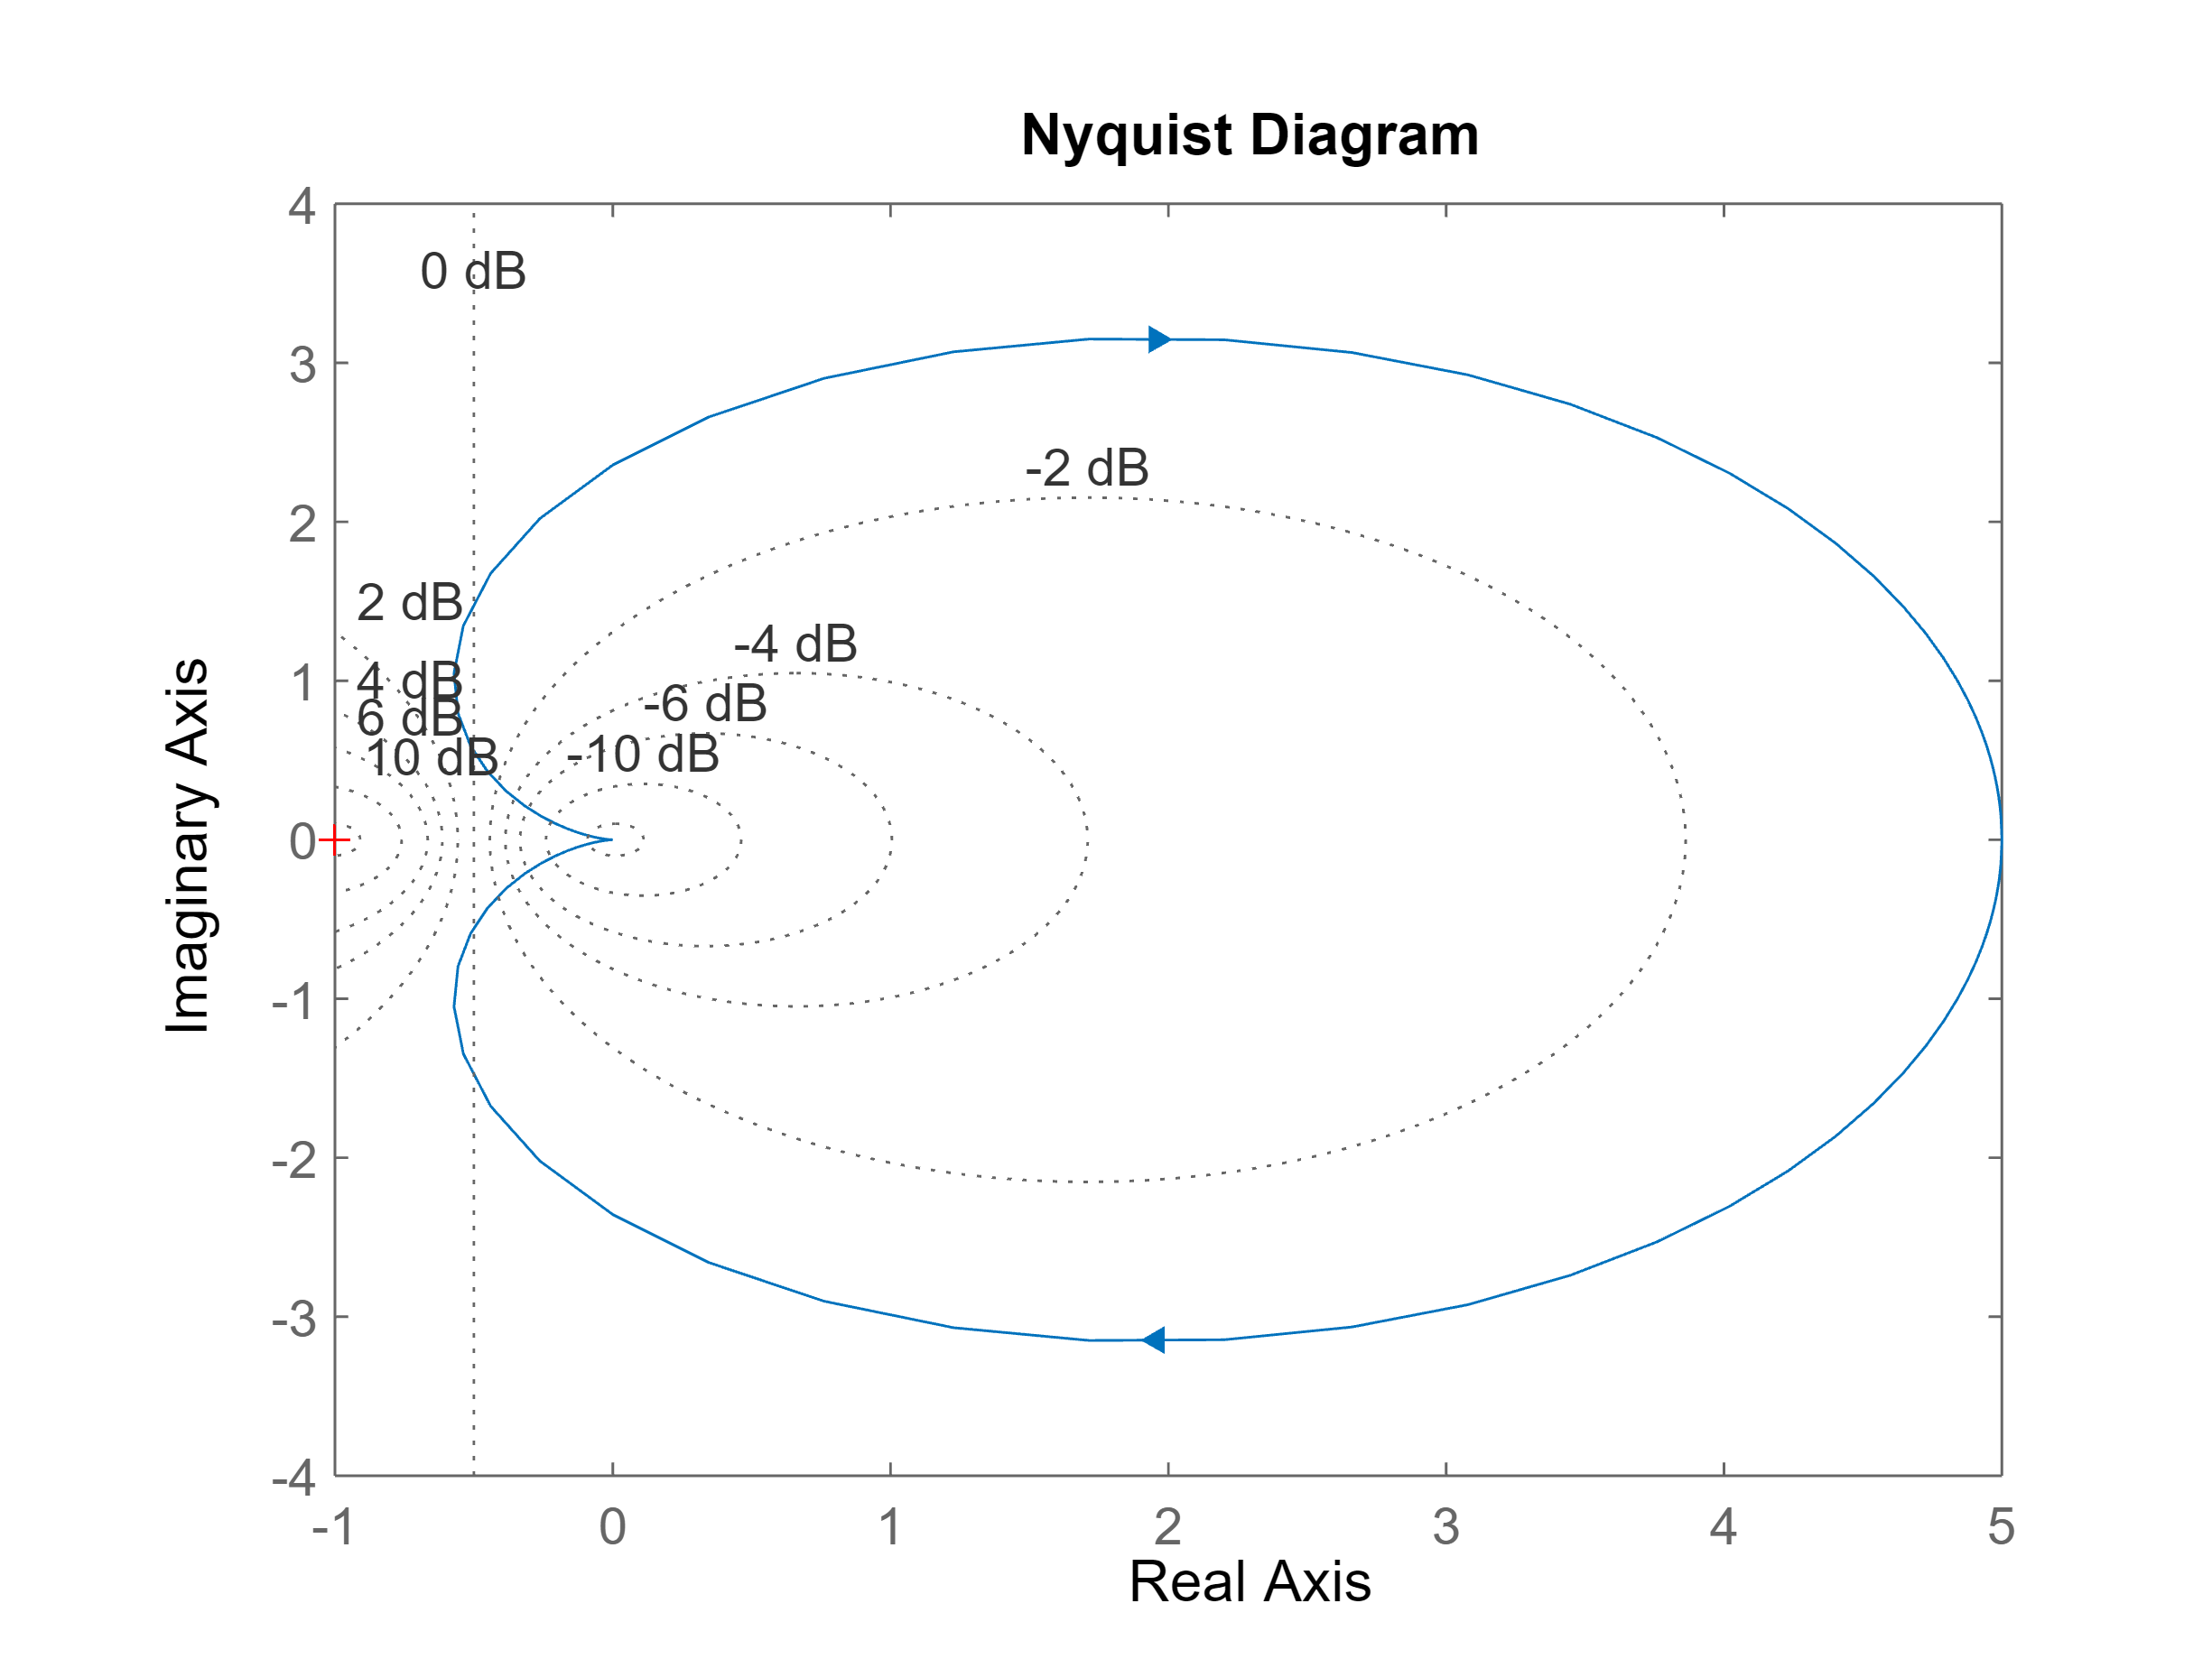

figure
nyquist(L), grid on

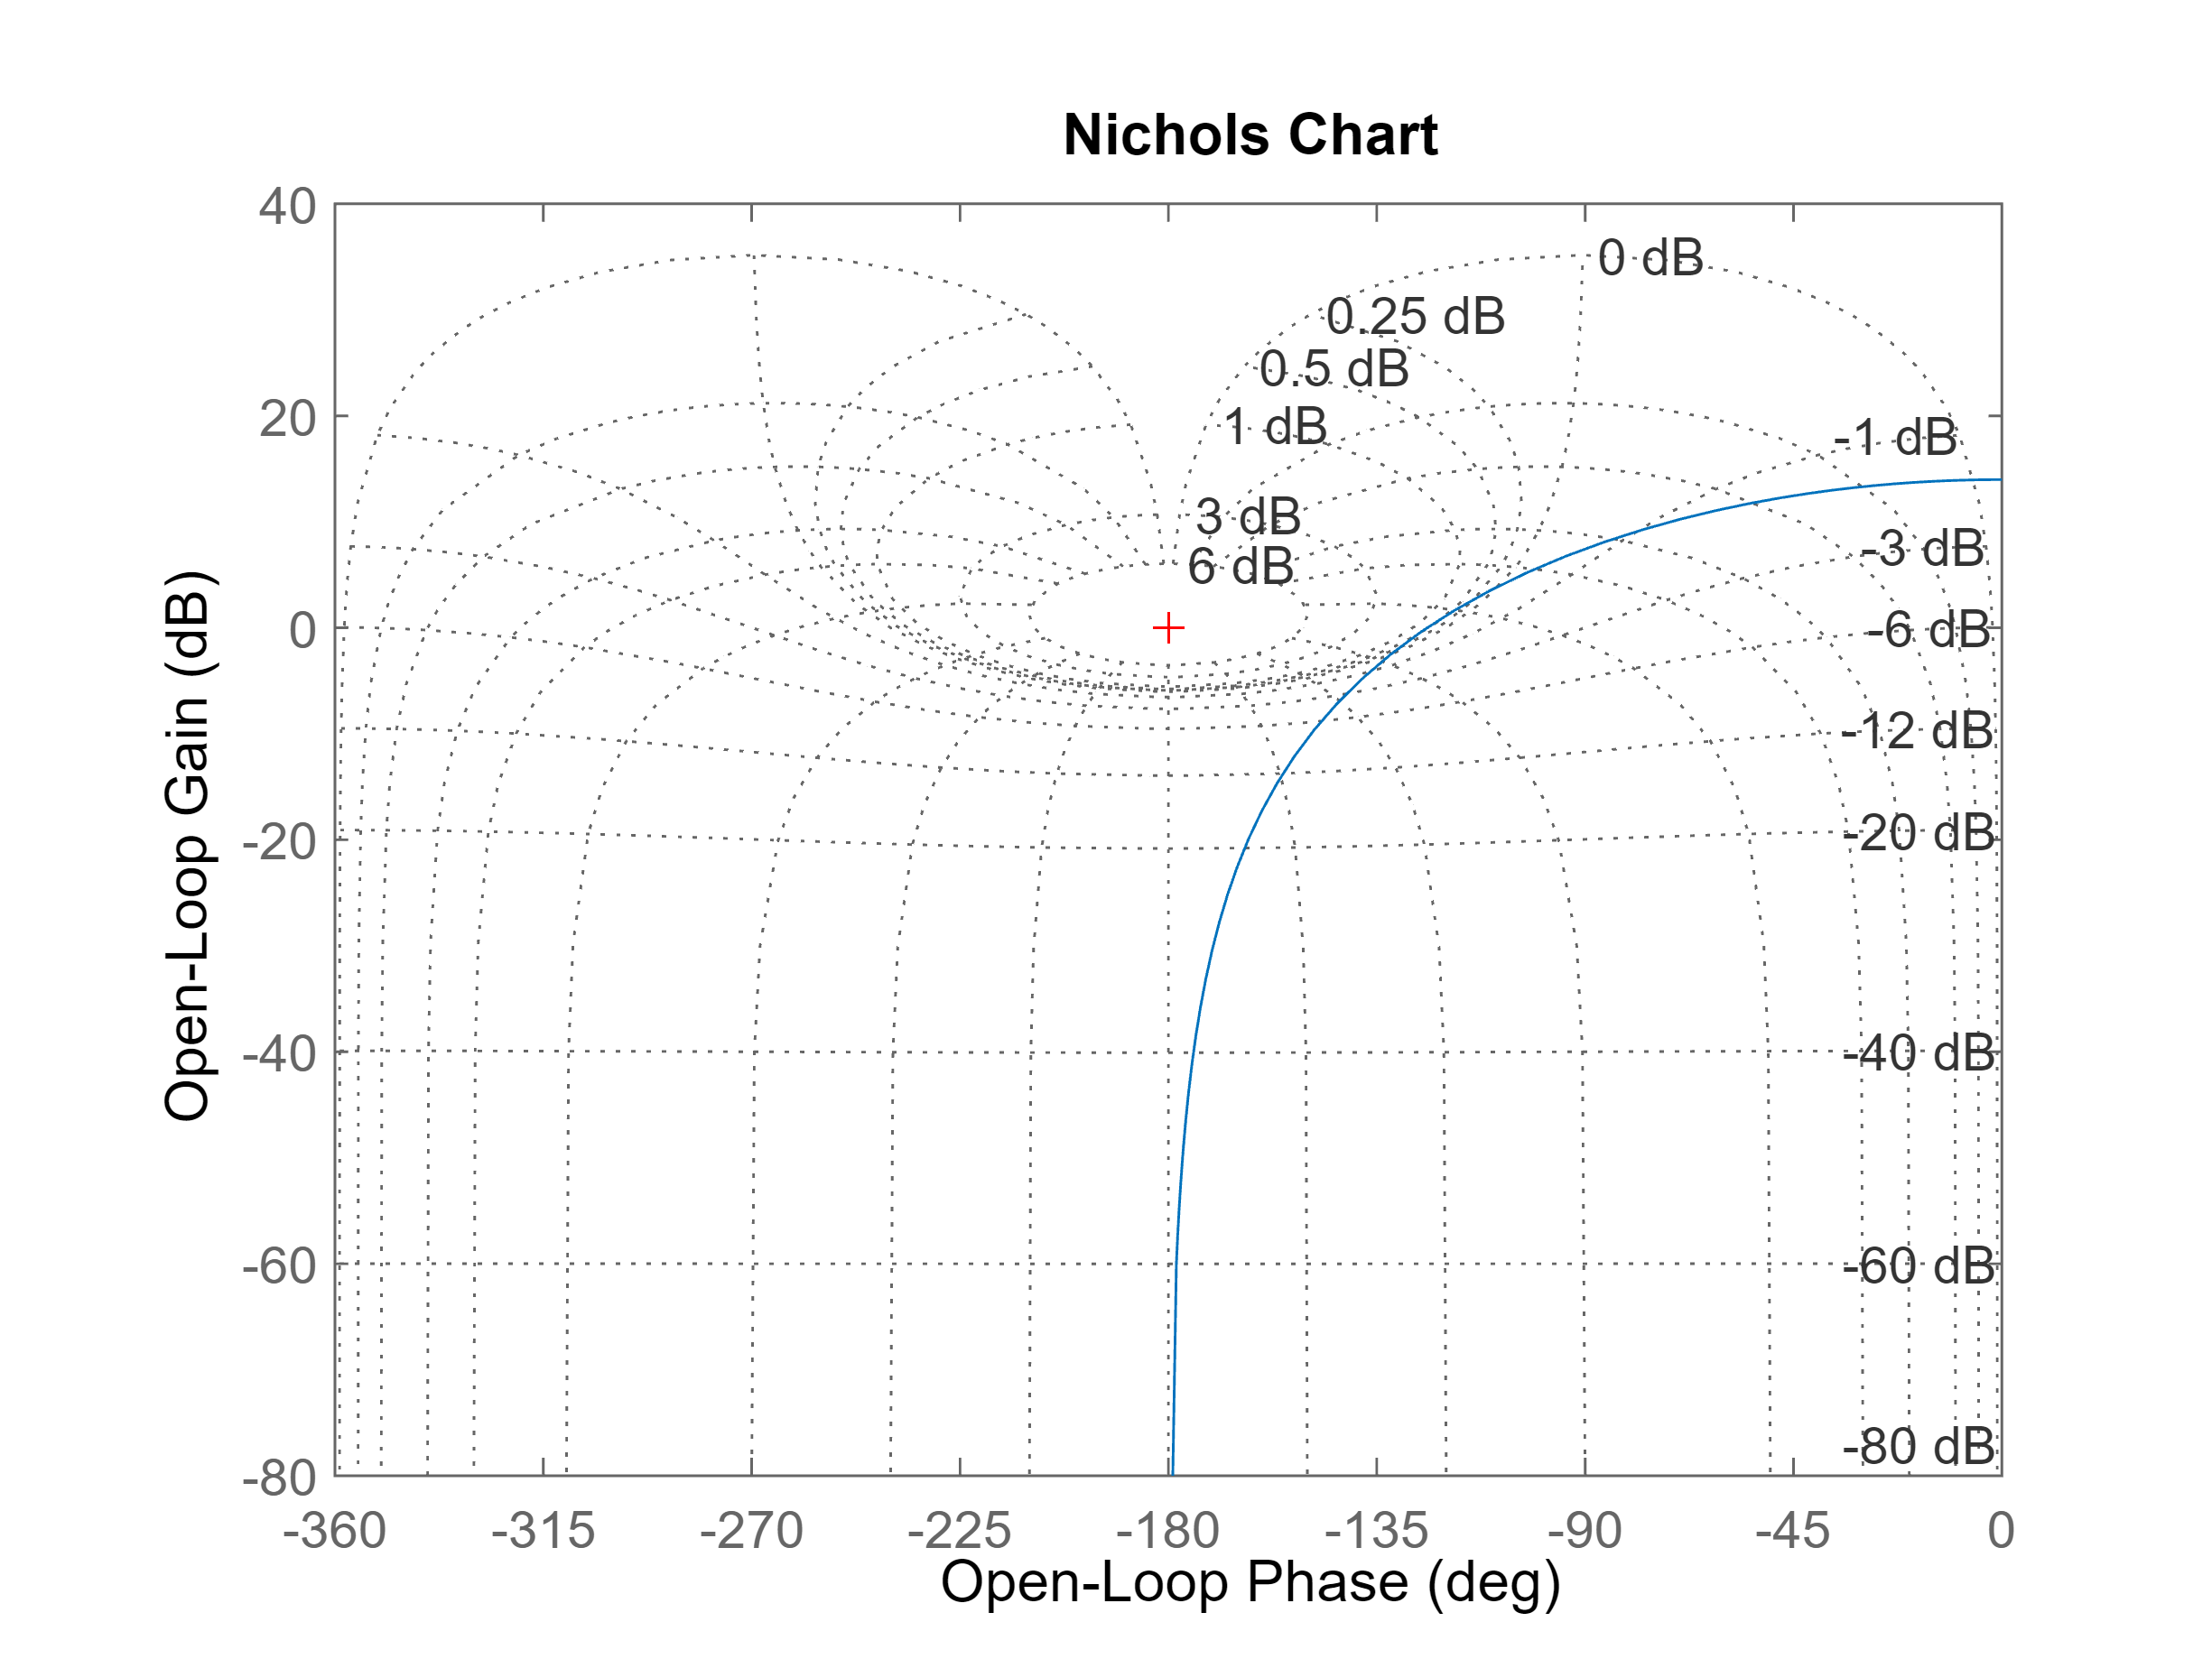

figure
nichols(L), grid on

## Regular stability

A system that becomes closed-loop unstable when a large control gain is applied.

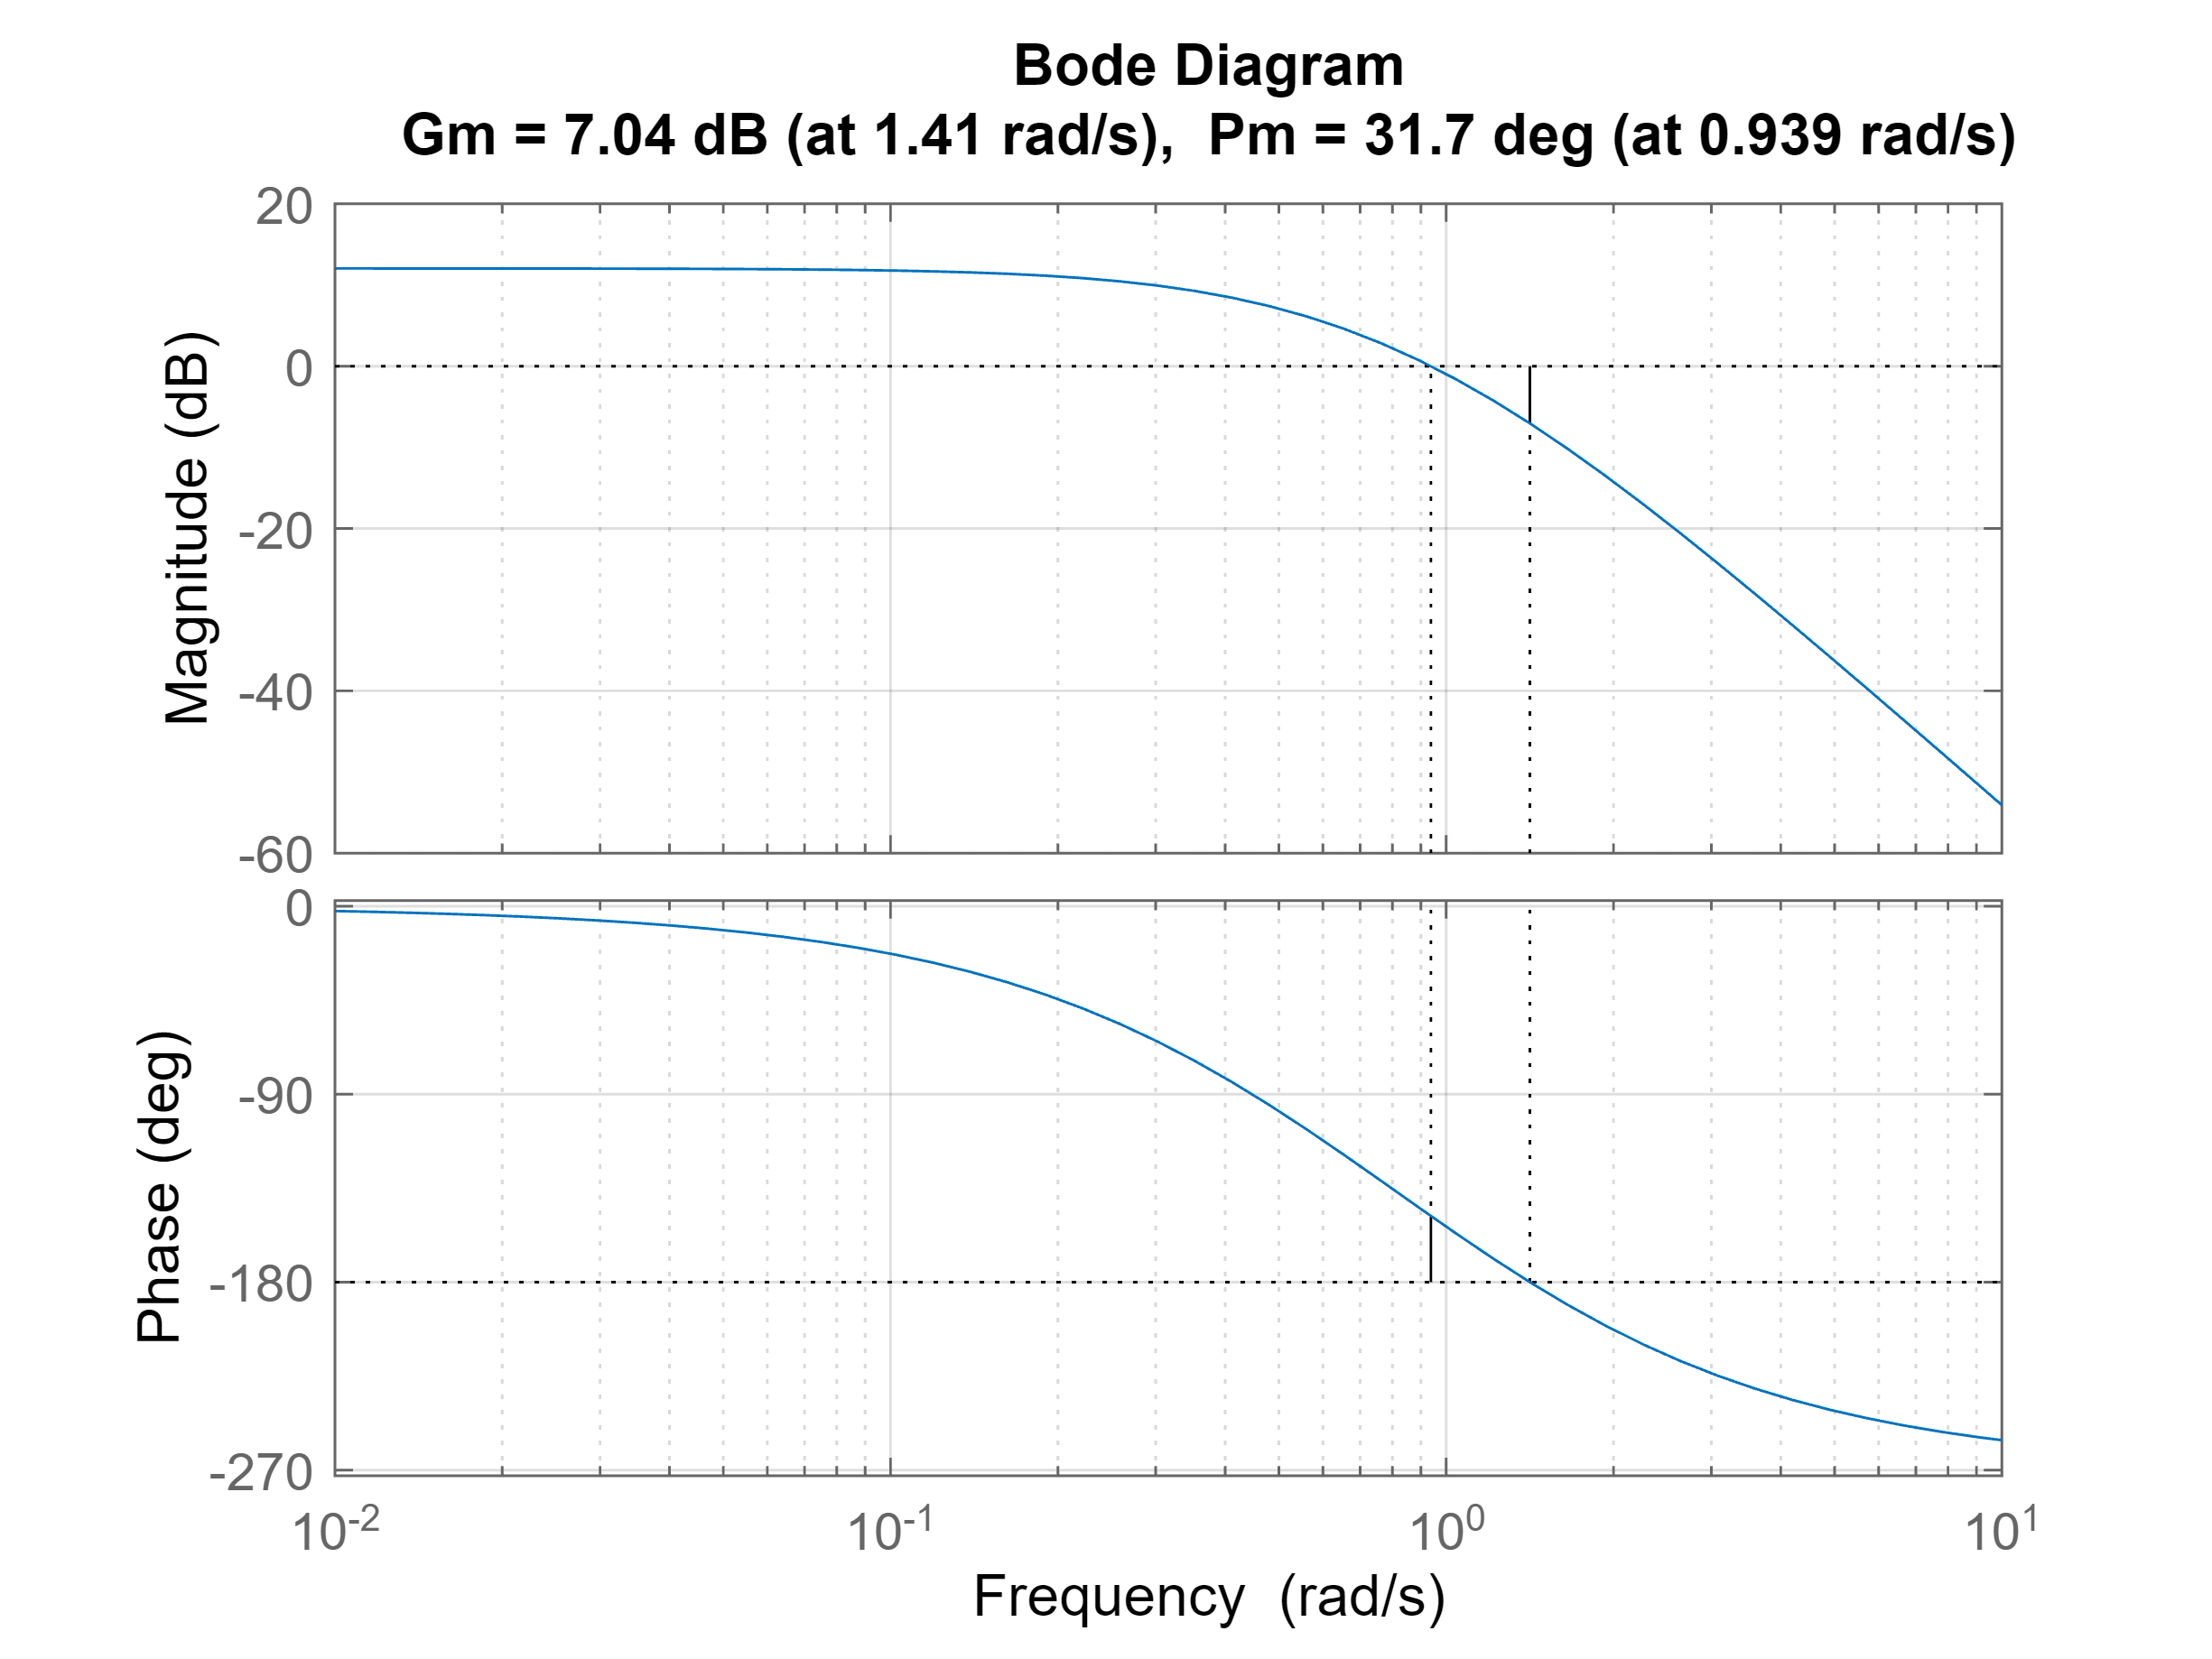

T1 = 1;
T2 = 2;
T3 = 1;
k = 4;

L = k/((1+s*T1)*(1+s*T2)*(1+s*T3));

figure
margin(L), grid on

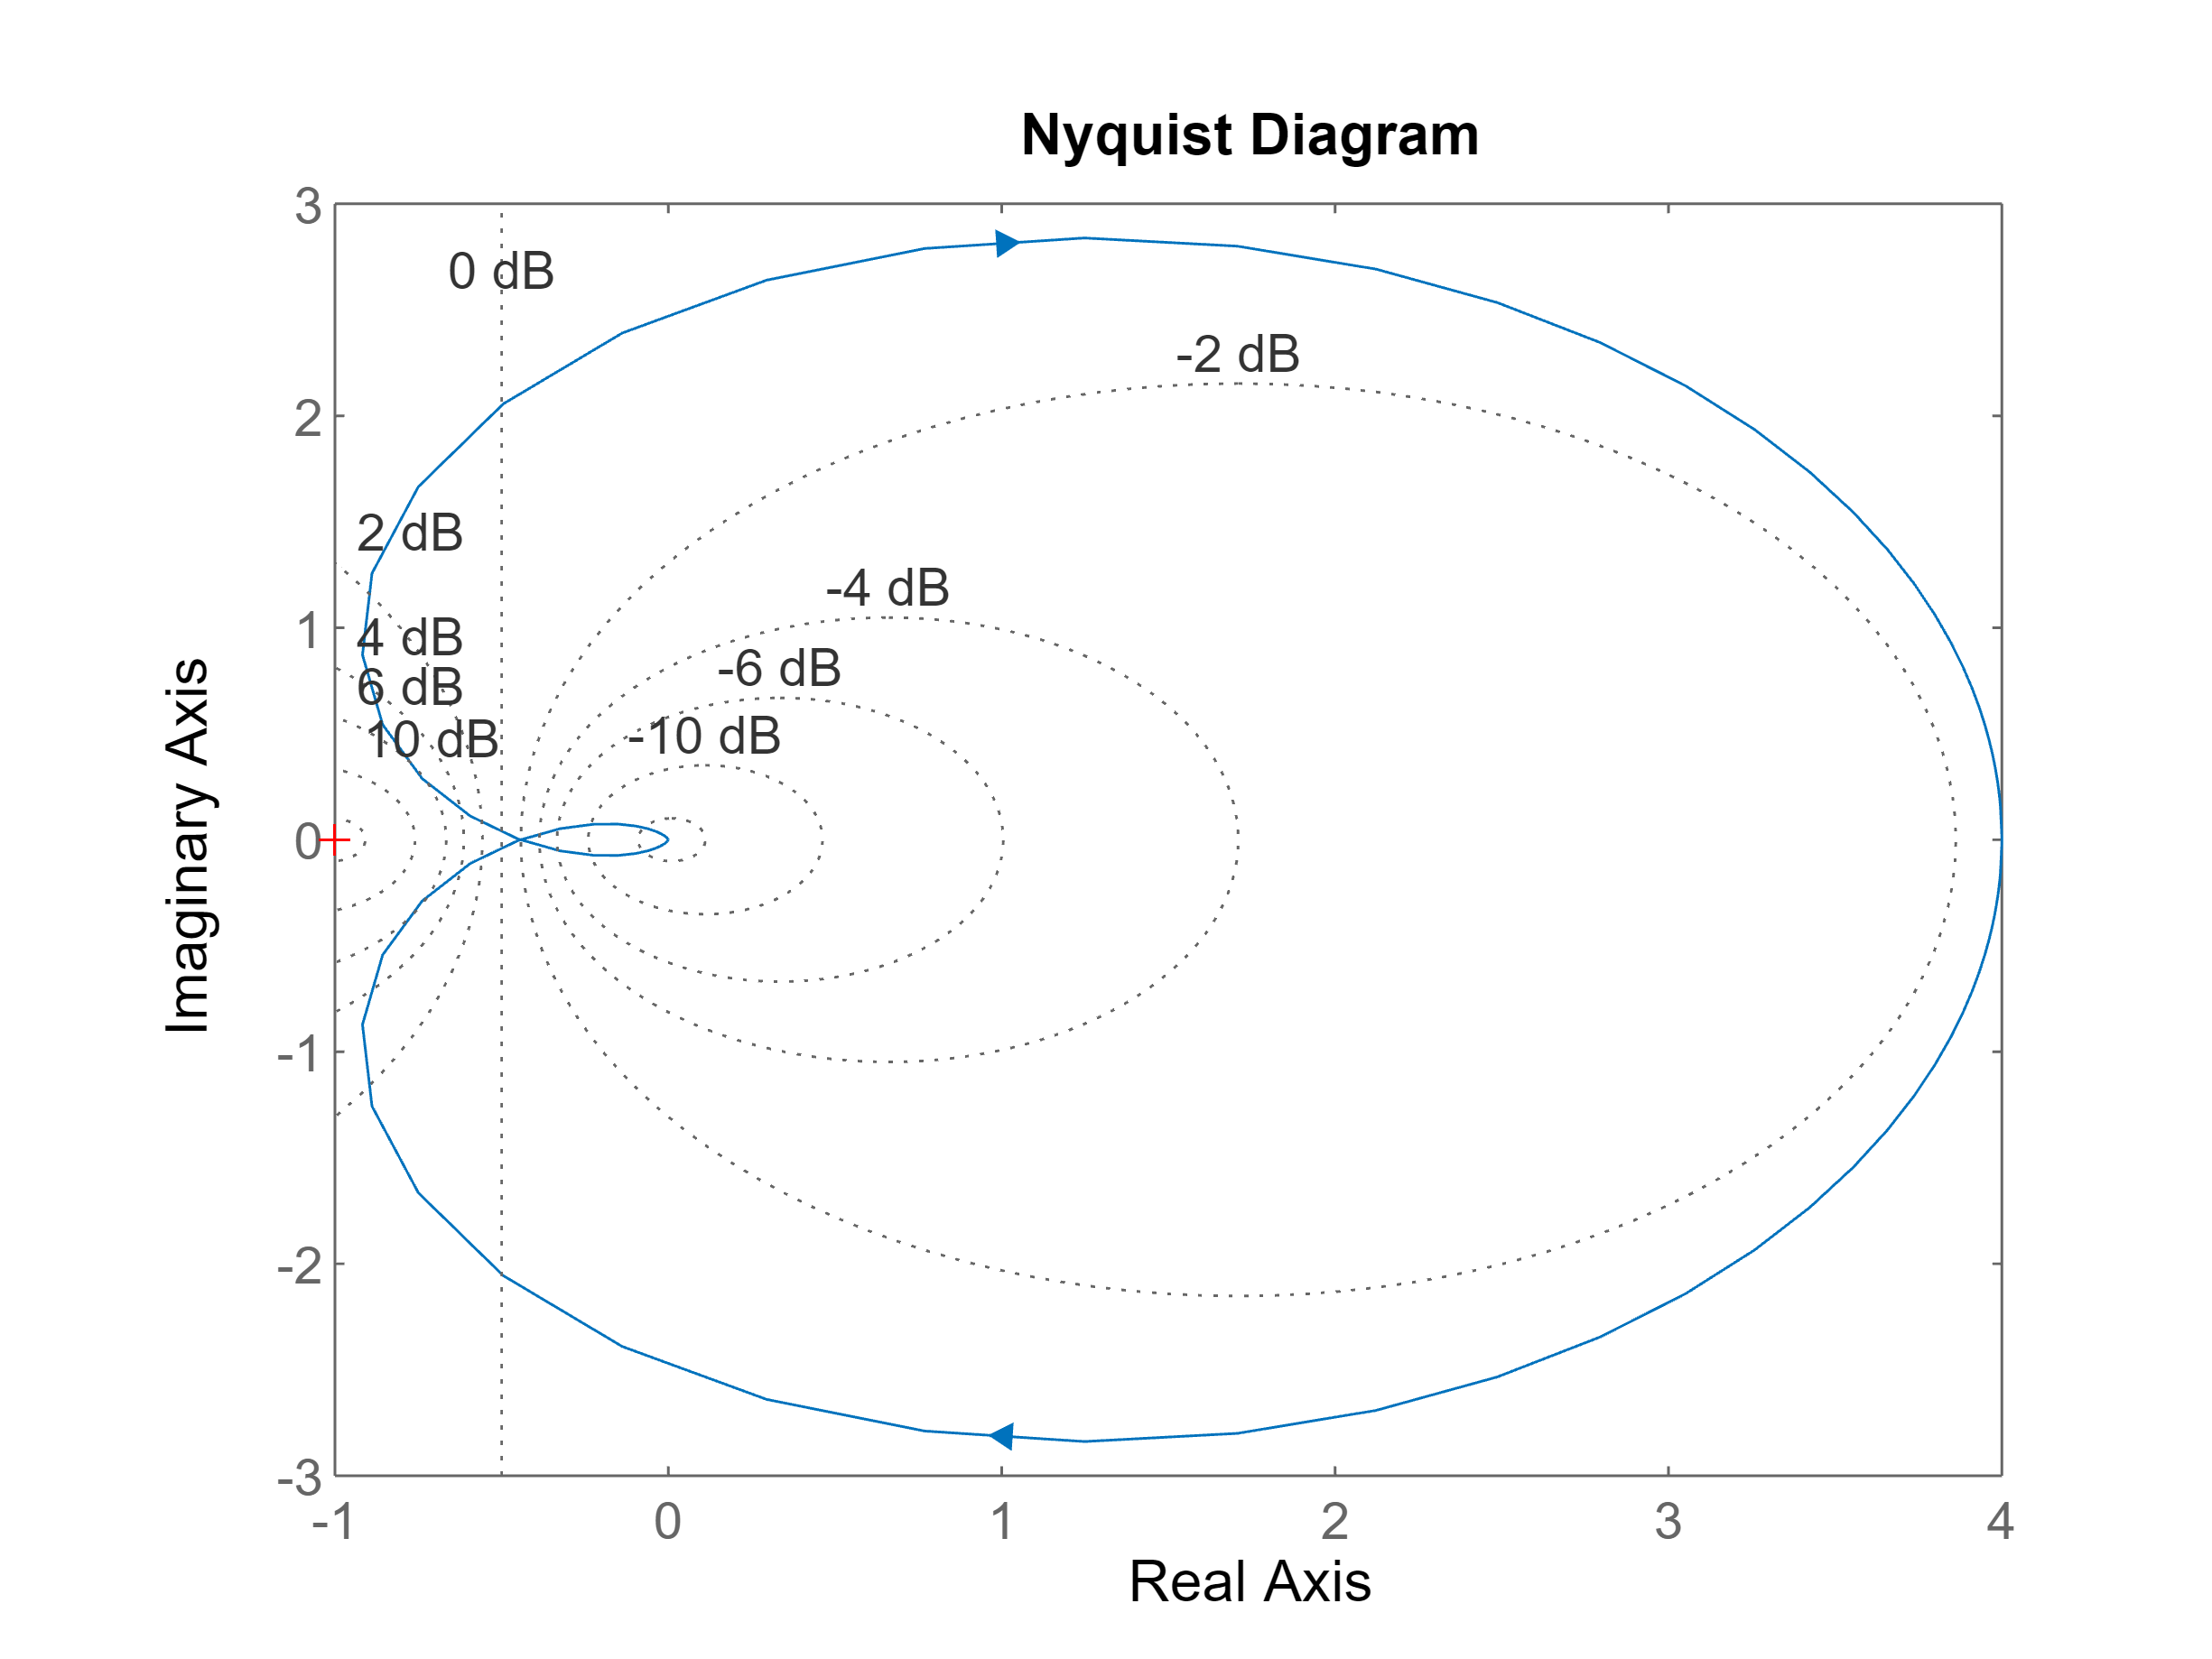

figure
nyquist(L), grid on

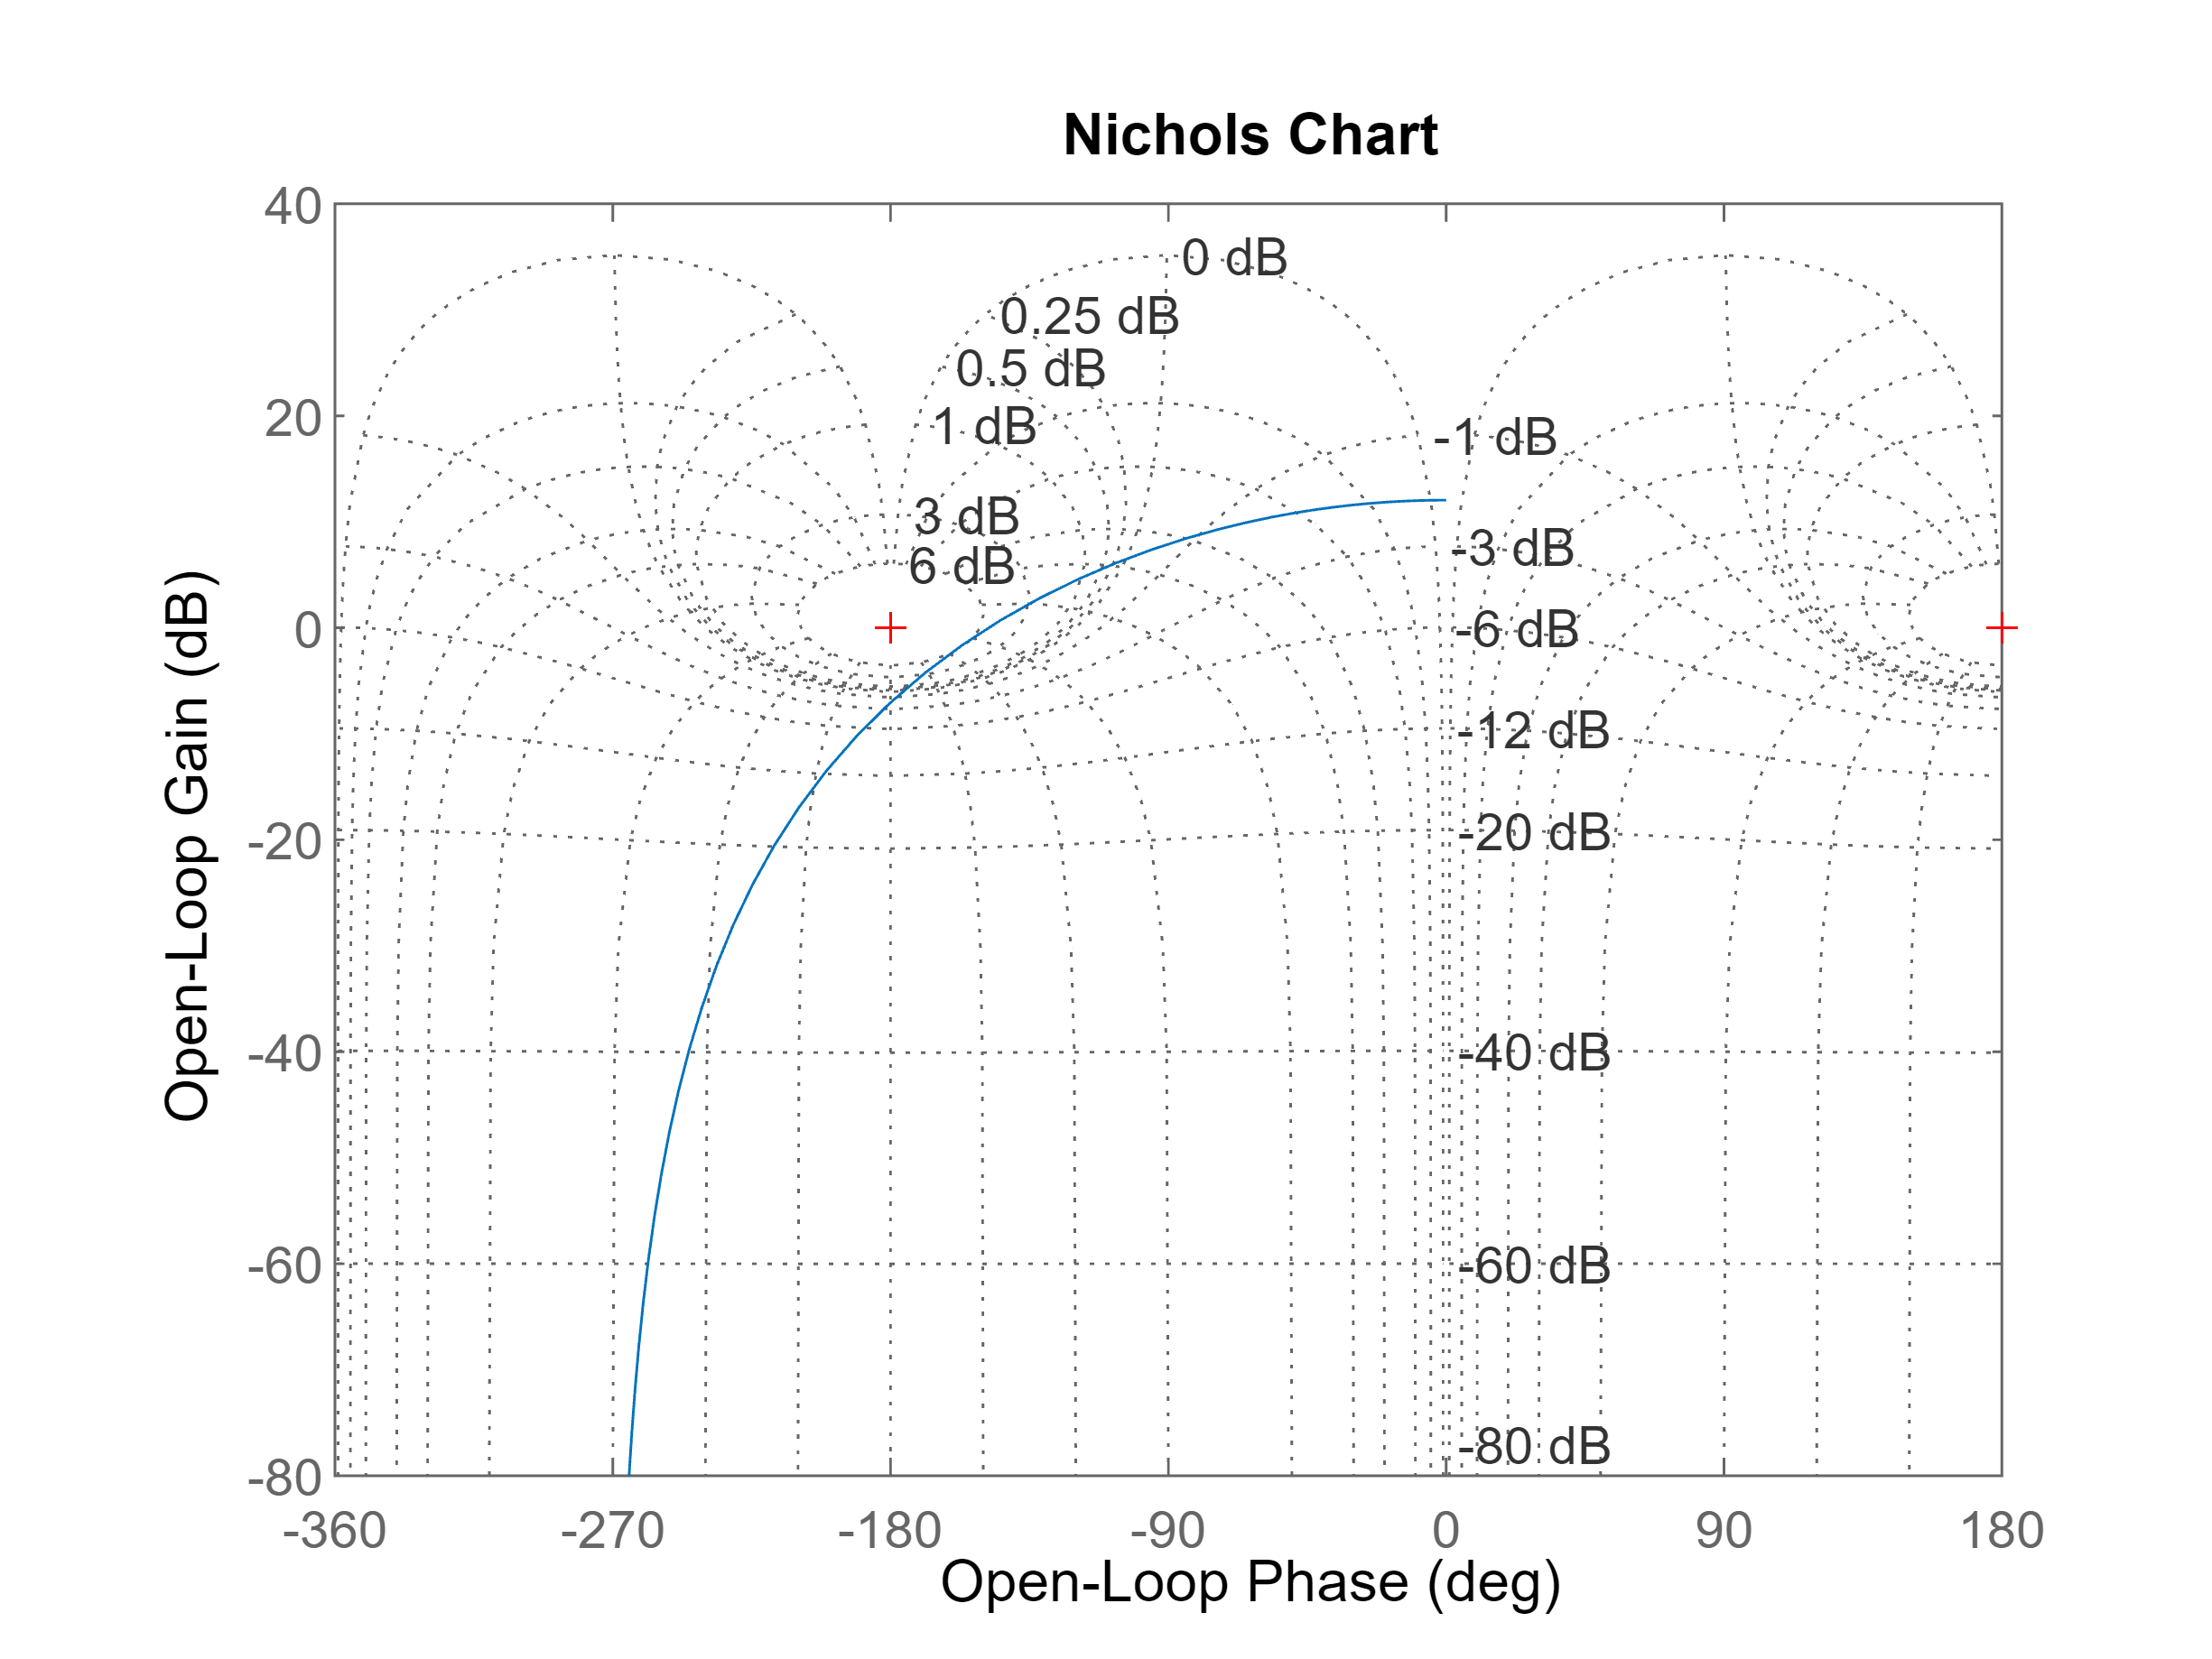

figure
nichols(L), grid on

A closed loop approximation for this system is:


$$F\left(s\right)=\frac{1}{1+2\zeta \frac{s\;}{\omega_{n\;} }+\frac{s^2 }{\omega_n^{2\;} }}$$


where


$$\zeta \approx \frac{\varphi_m }{100},{\;\;\;\omega }_n \approx \omega_{c\;}$$


NOTE: the number of poles in the origin of L is not sufficient to guarantee zero error at steady state. We already know that we will have an error at low frequencies by approximating F as above. We can explicitly account for this by adding a factor of 1 - 1/(1+L0) in the approximated F.

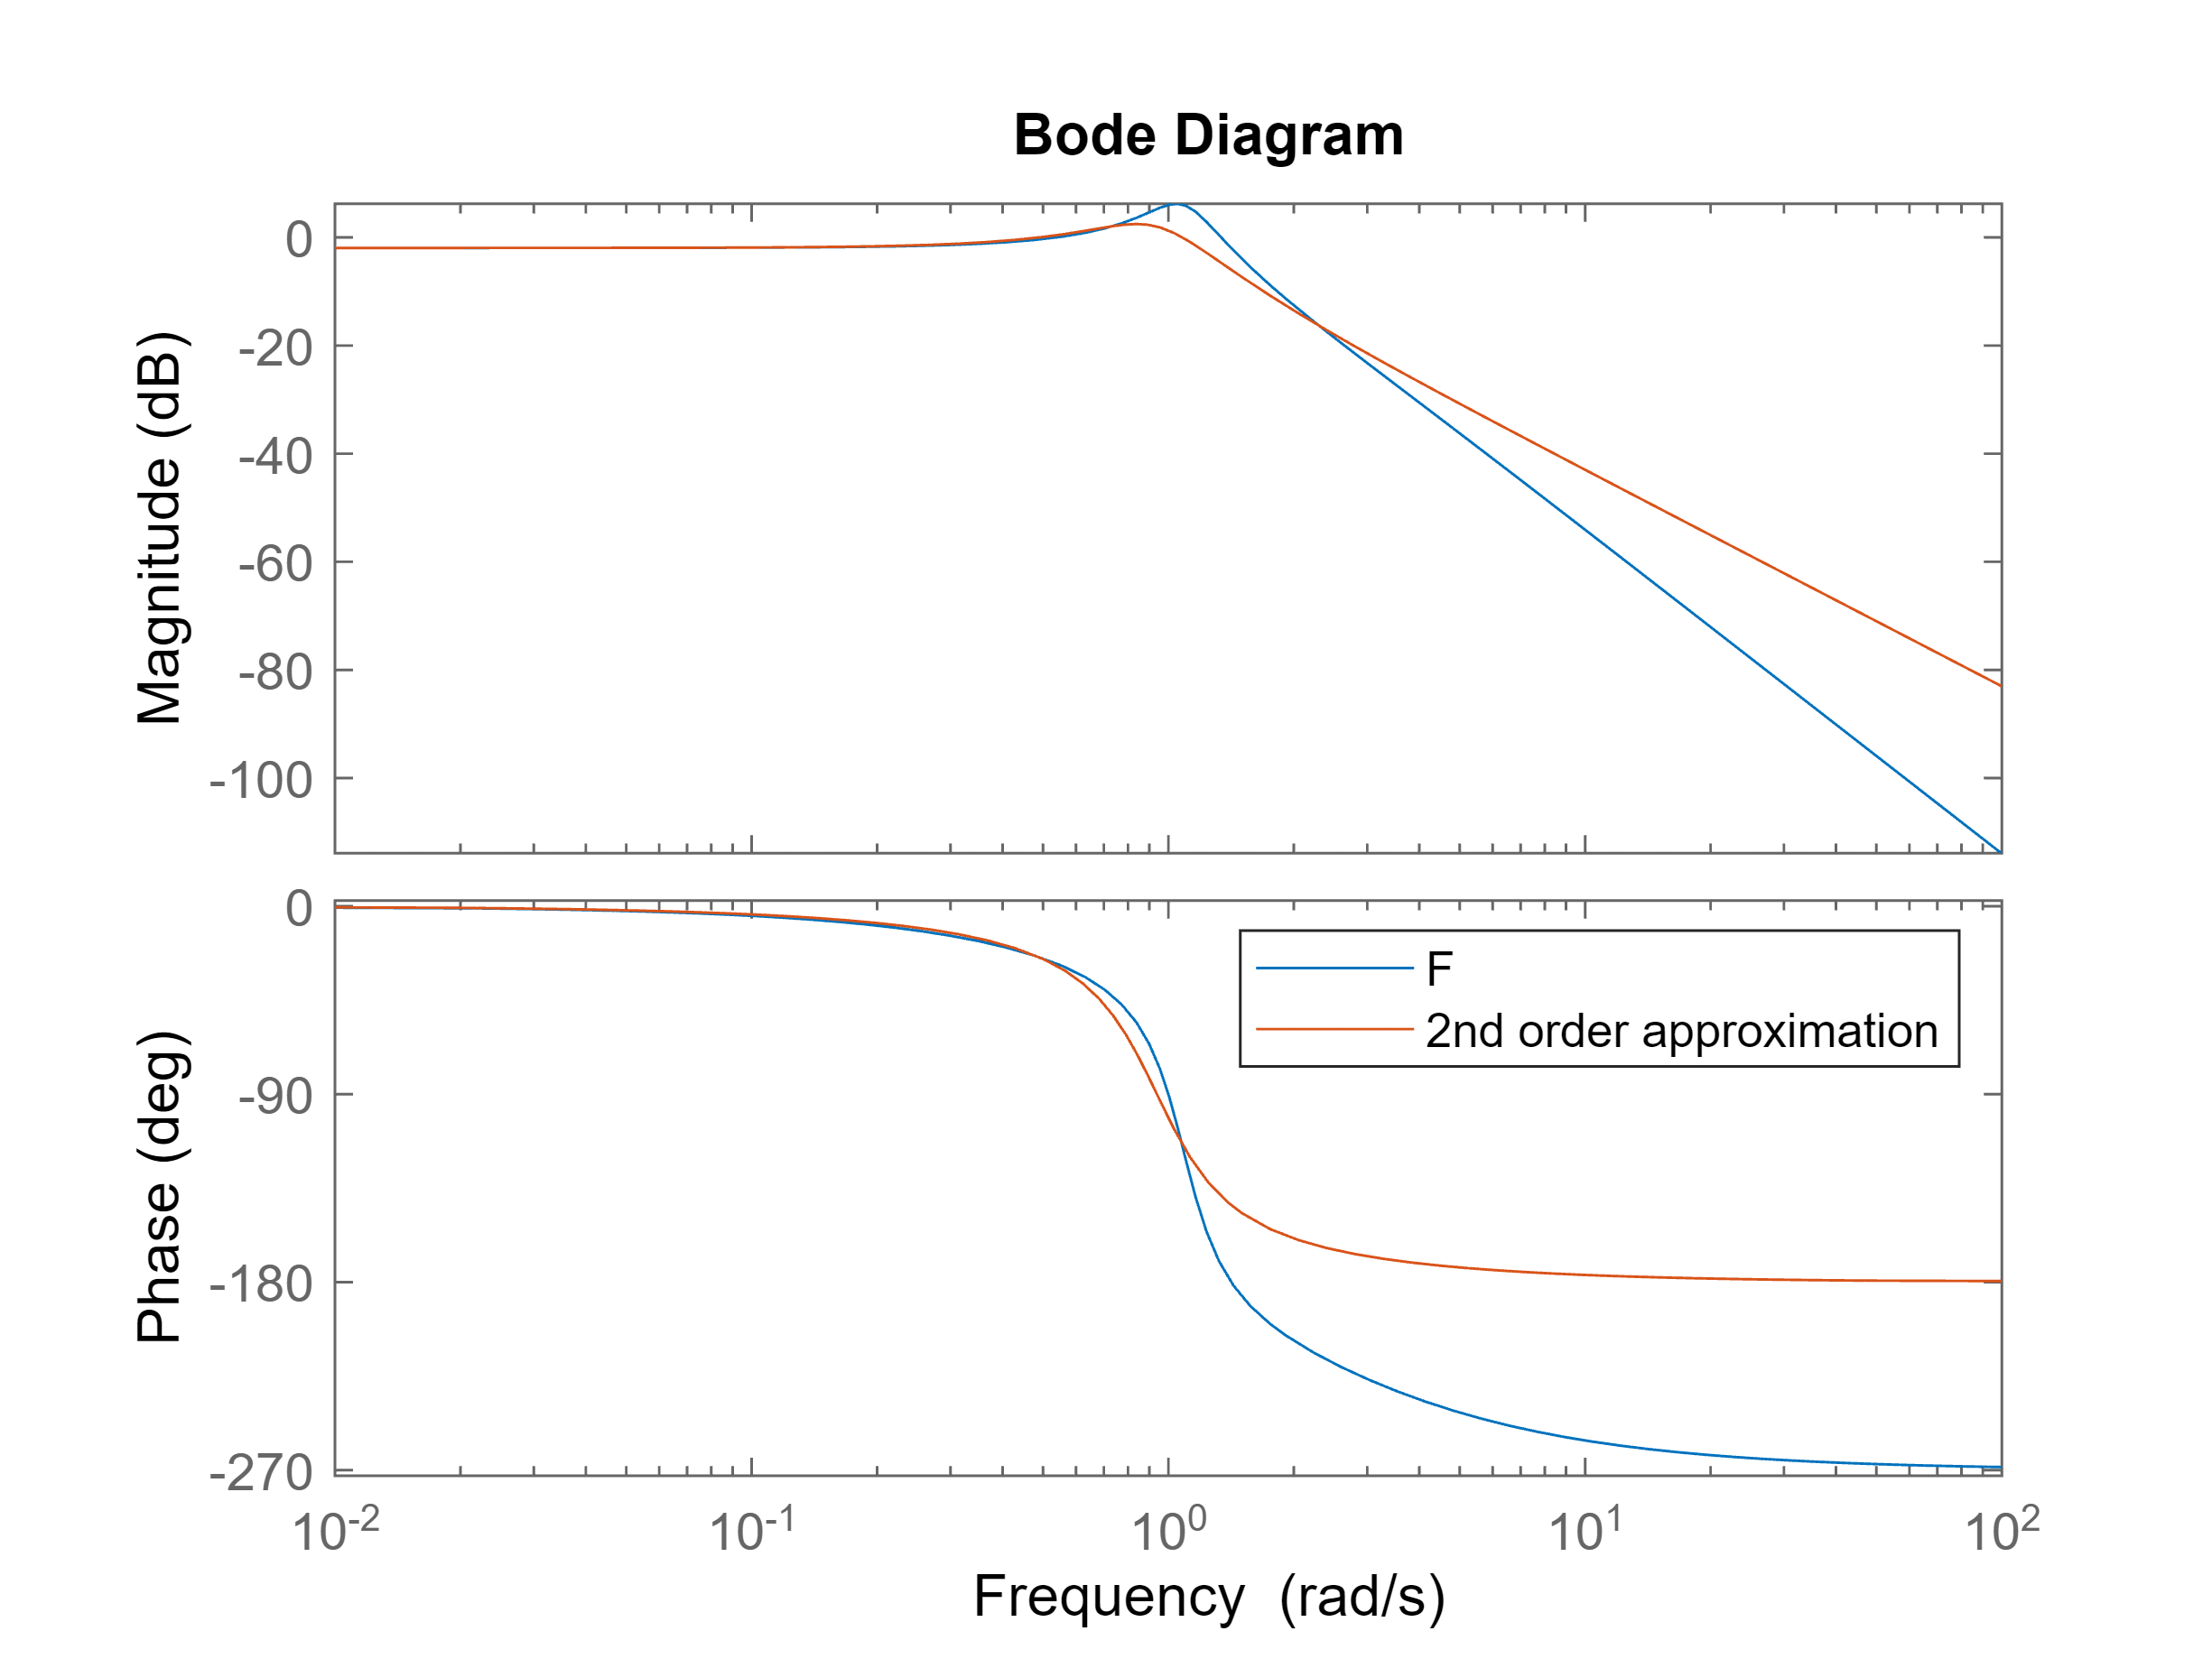

[GM,PM,wcg,wcp] = margin(L);

zeta = PM/100;
wn = wcp;

L0 = dcgain(L);

F_approx = 1/(1+2*zeta*s/wn + s^2/wn^2) *  (1 - 1/(1+L0));
F = feedback(L,1);

bode(F,F_approx)
legend('F','2nd order approximation')

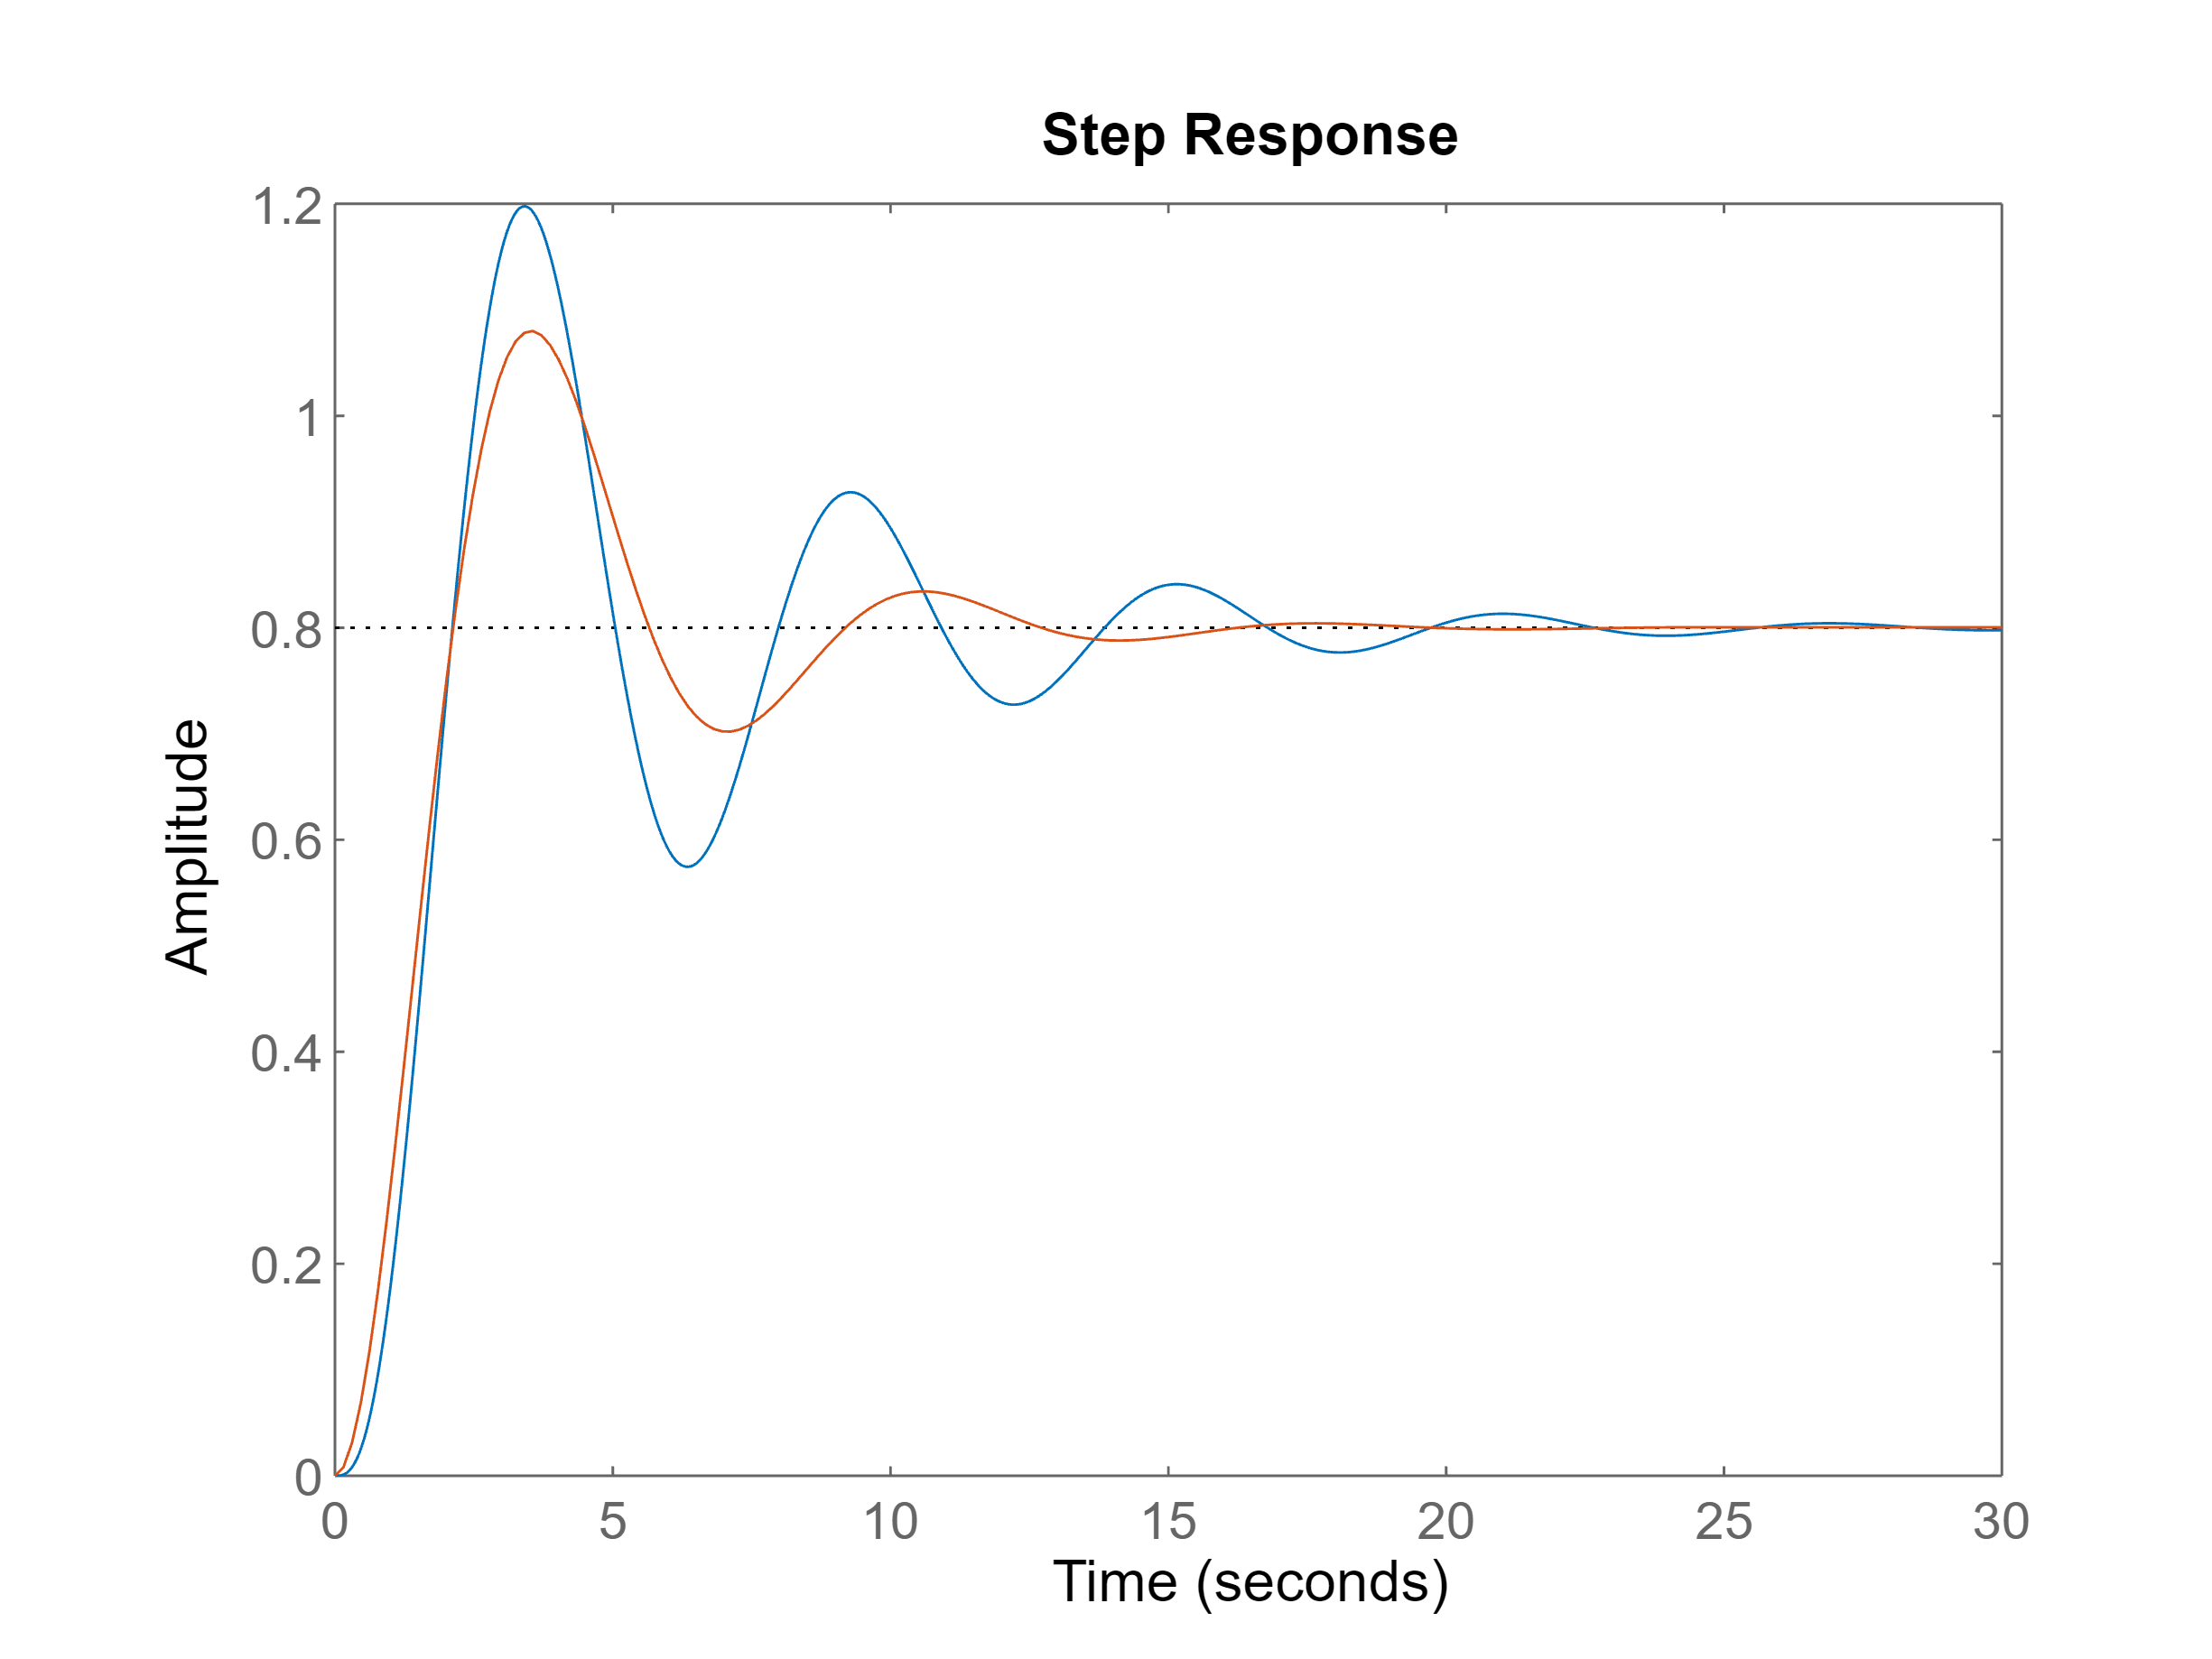

step(F,F_approx)

## Paradoxical stability

A system that becomes closed-loop stable when a large gain is applied.

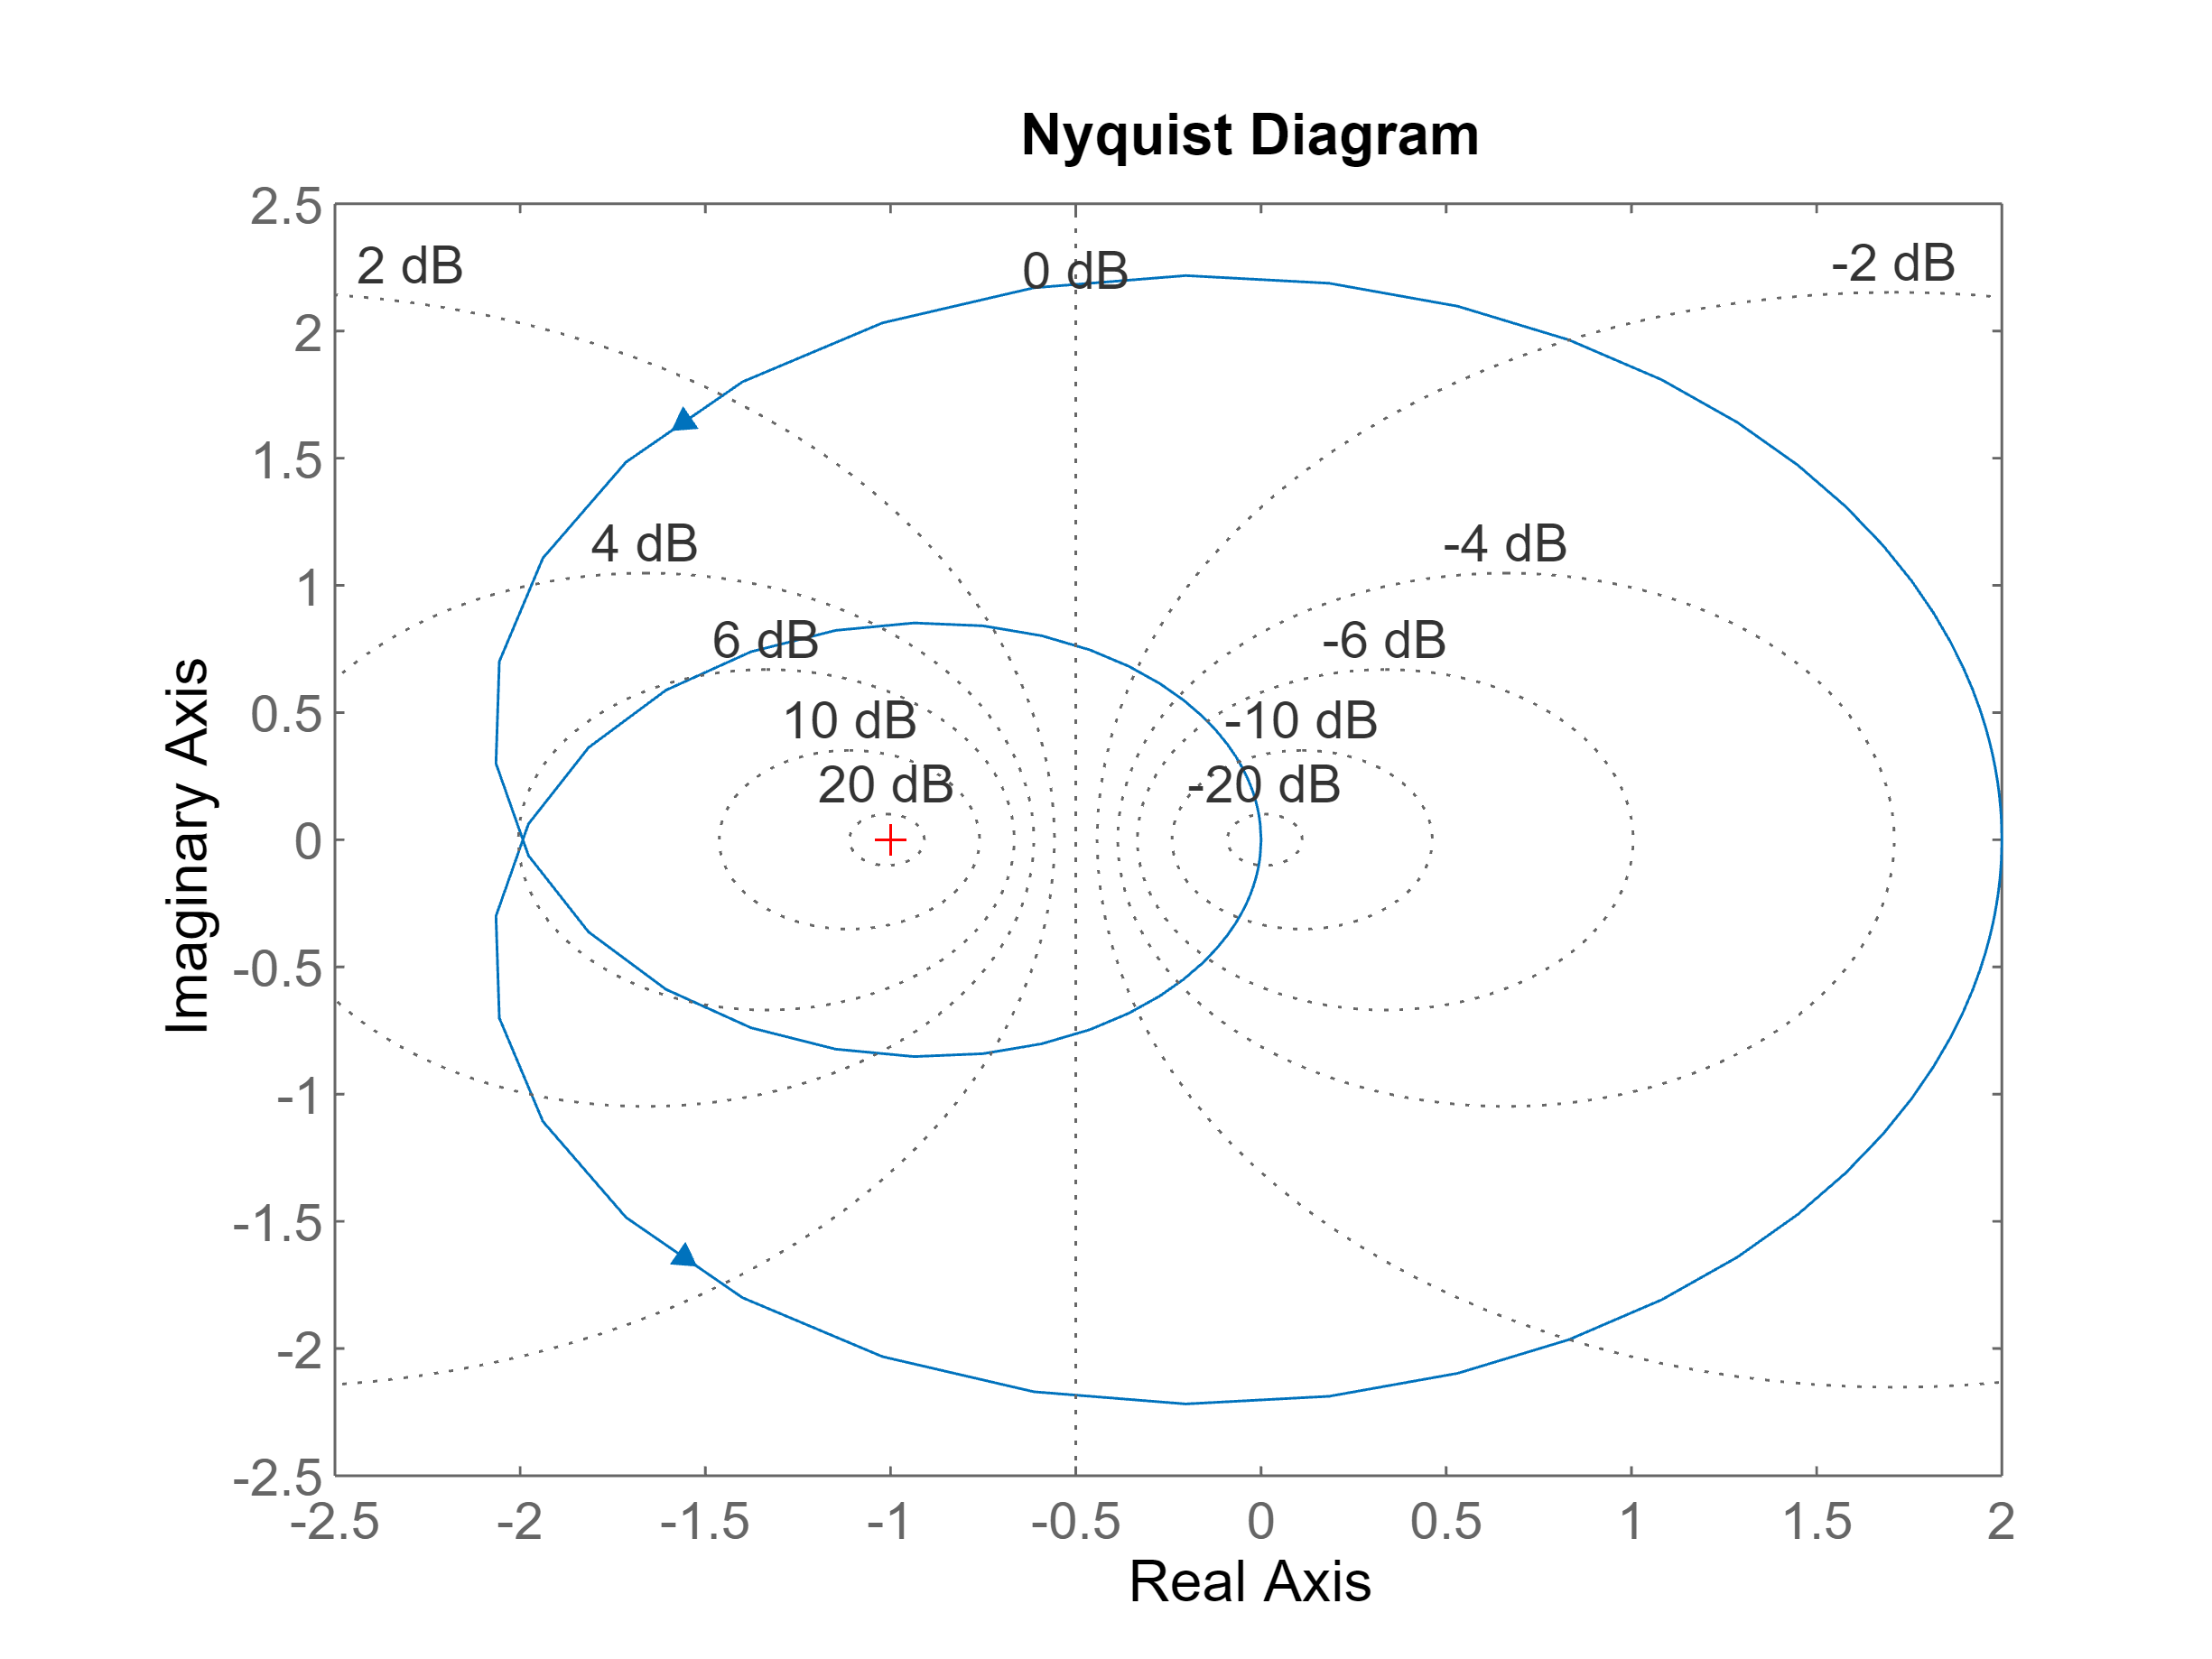

T1 = -1;
T2 = -2;
T0 = 3;

k = 2;

L = k*(1+s*T0)/((1+s*T1)*(1+s*T2));

figure
nyquist(L), grid on

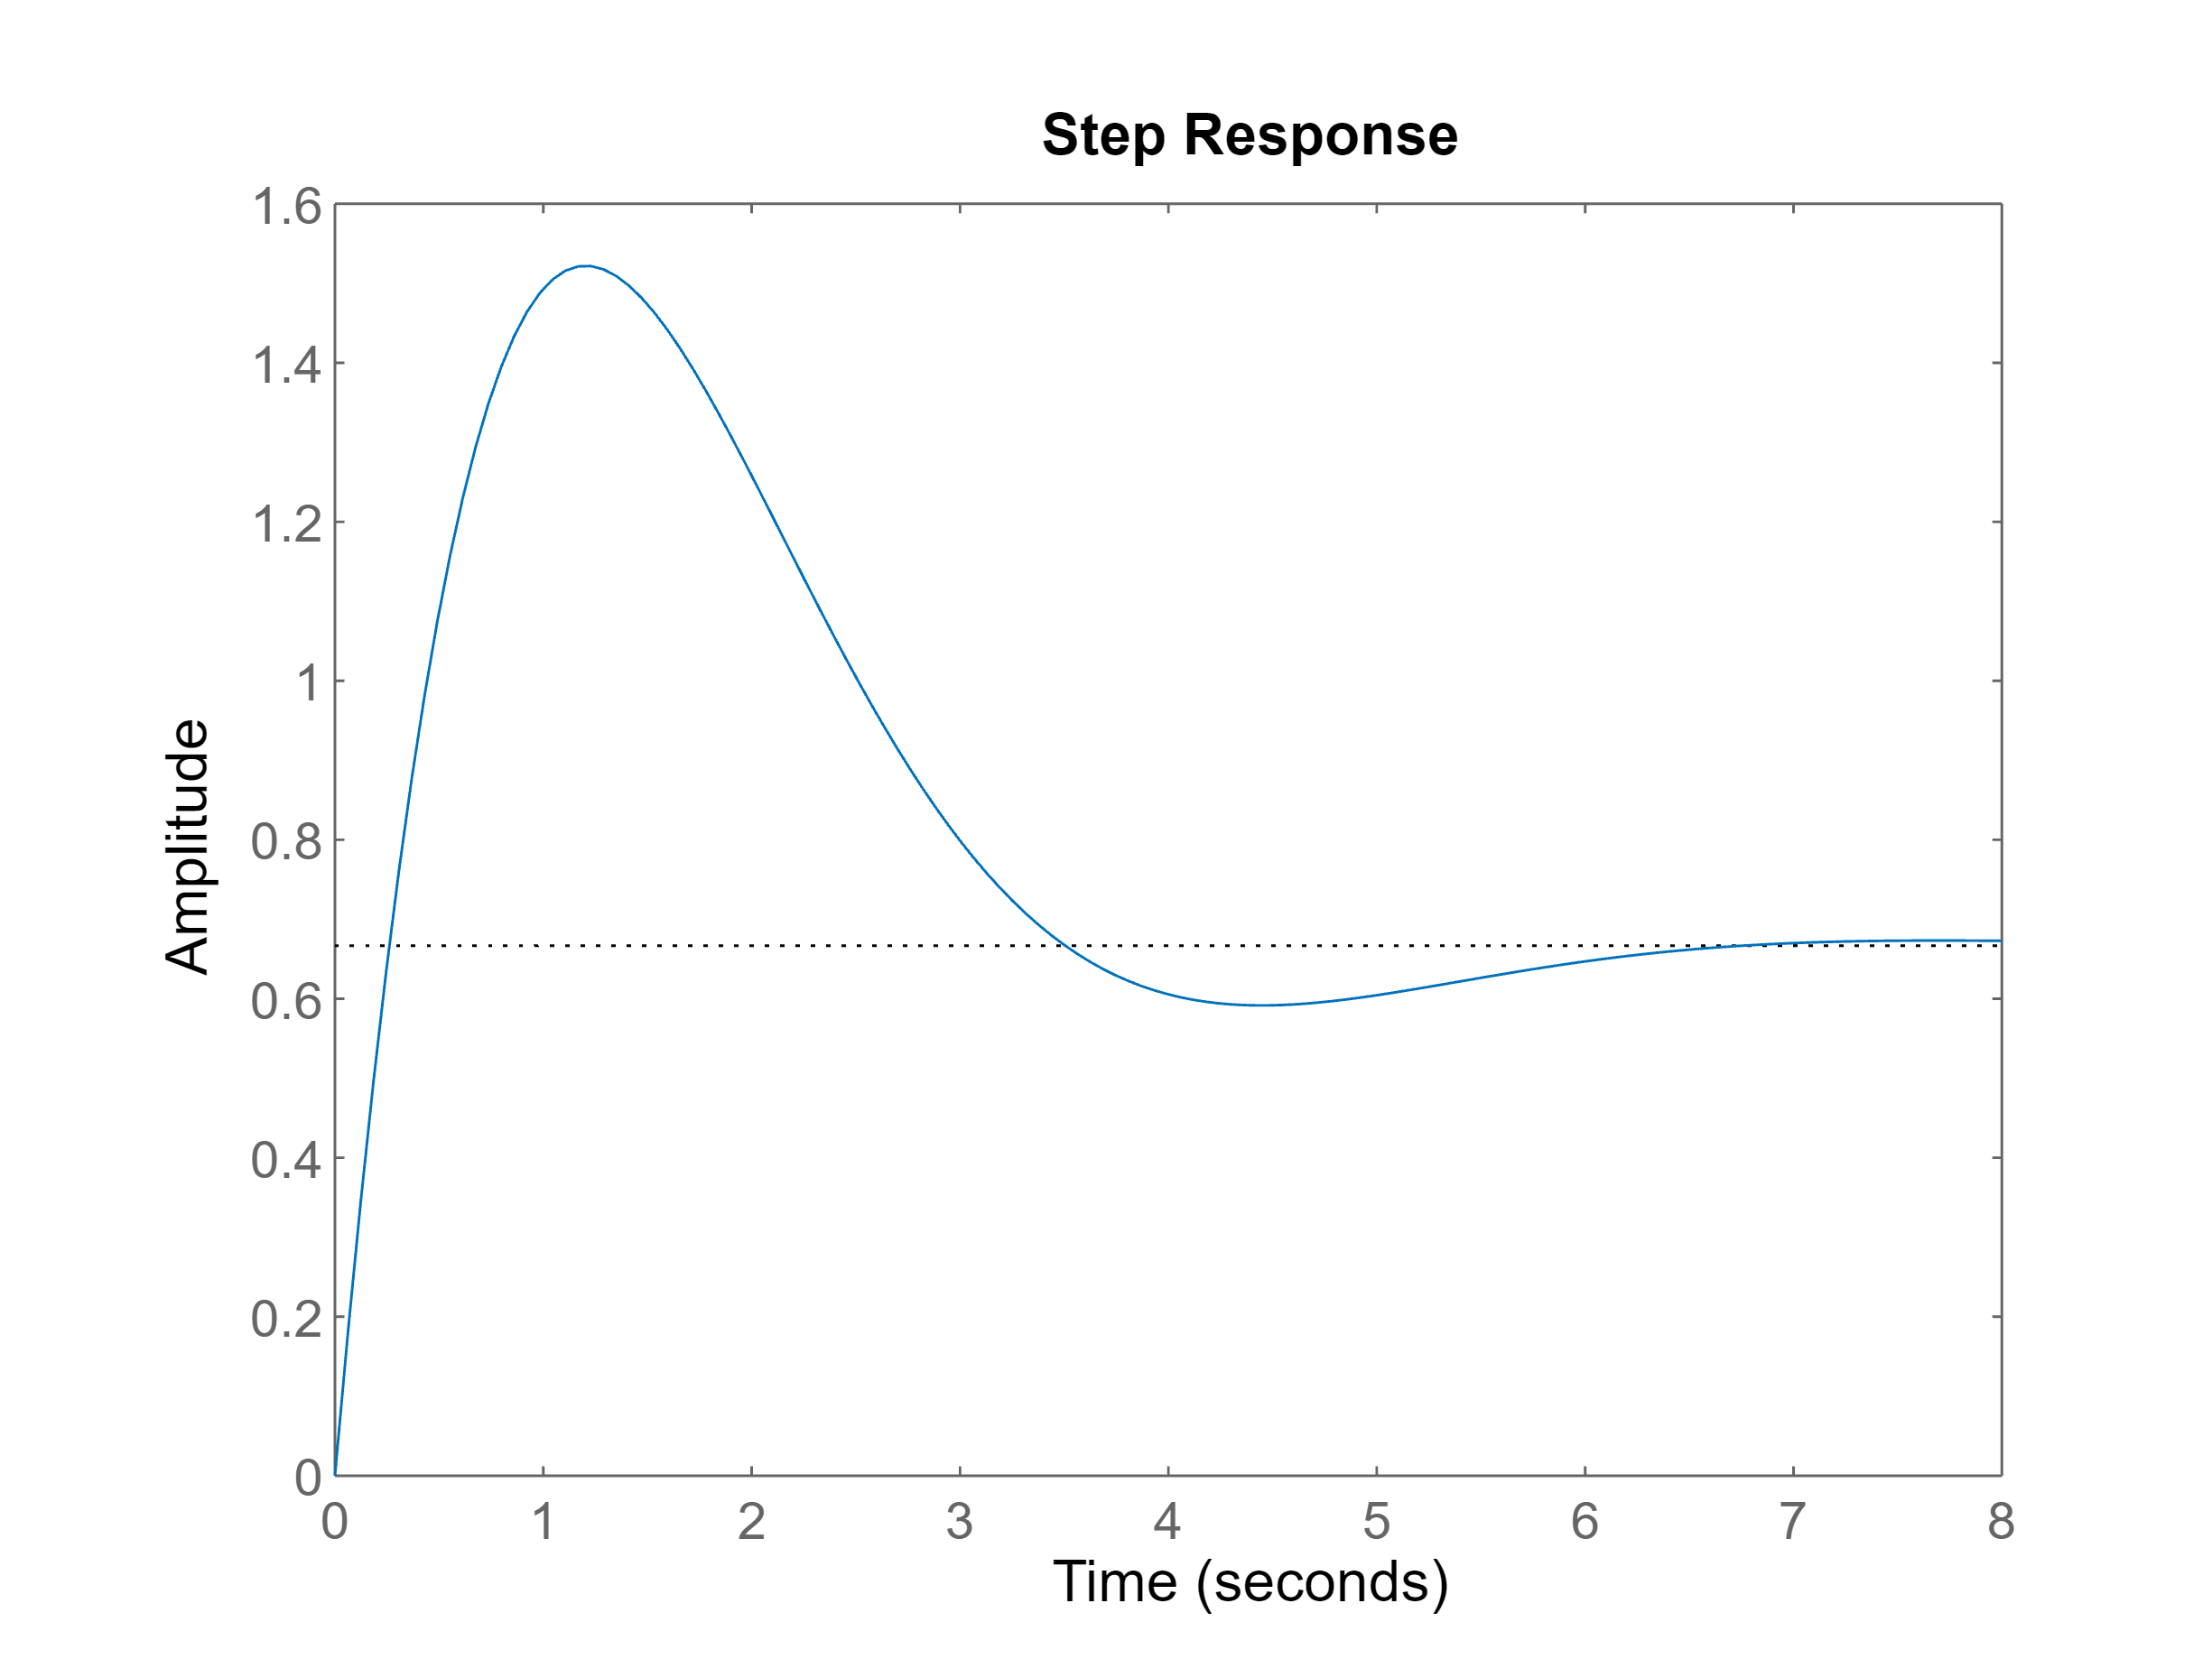

step(feedback(L,1))

## Conditioned stability

Closed-loop stability depends on the gain in a 'non-monotonic' way.

T01 = 0.3; 
T02 = 0.1;

T1 = 2;
T2 = 0.01;
T3 = 0.0003;

k = 100;

L = ((1+s*T01)*(1+s*T02)) / (s^2*(1+s*T1)*(1+s*T2))%*(1+s*T3));

L =
 
    0.03 s^2 + 0.4 s + 1
  -------------------------
  0.02 s^4 + 2.01 s^3 + s^2
 
Continuous-time transfer function.



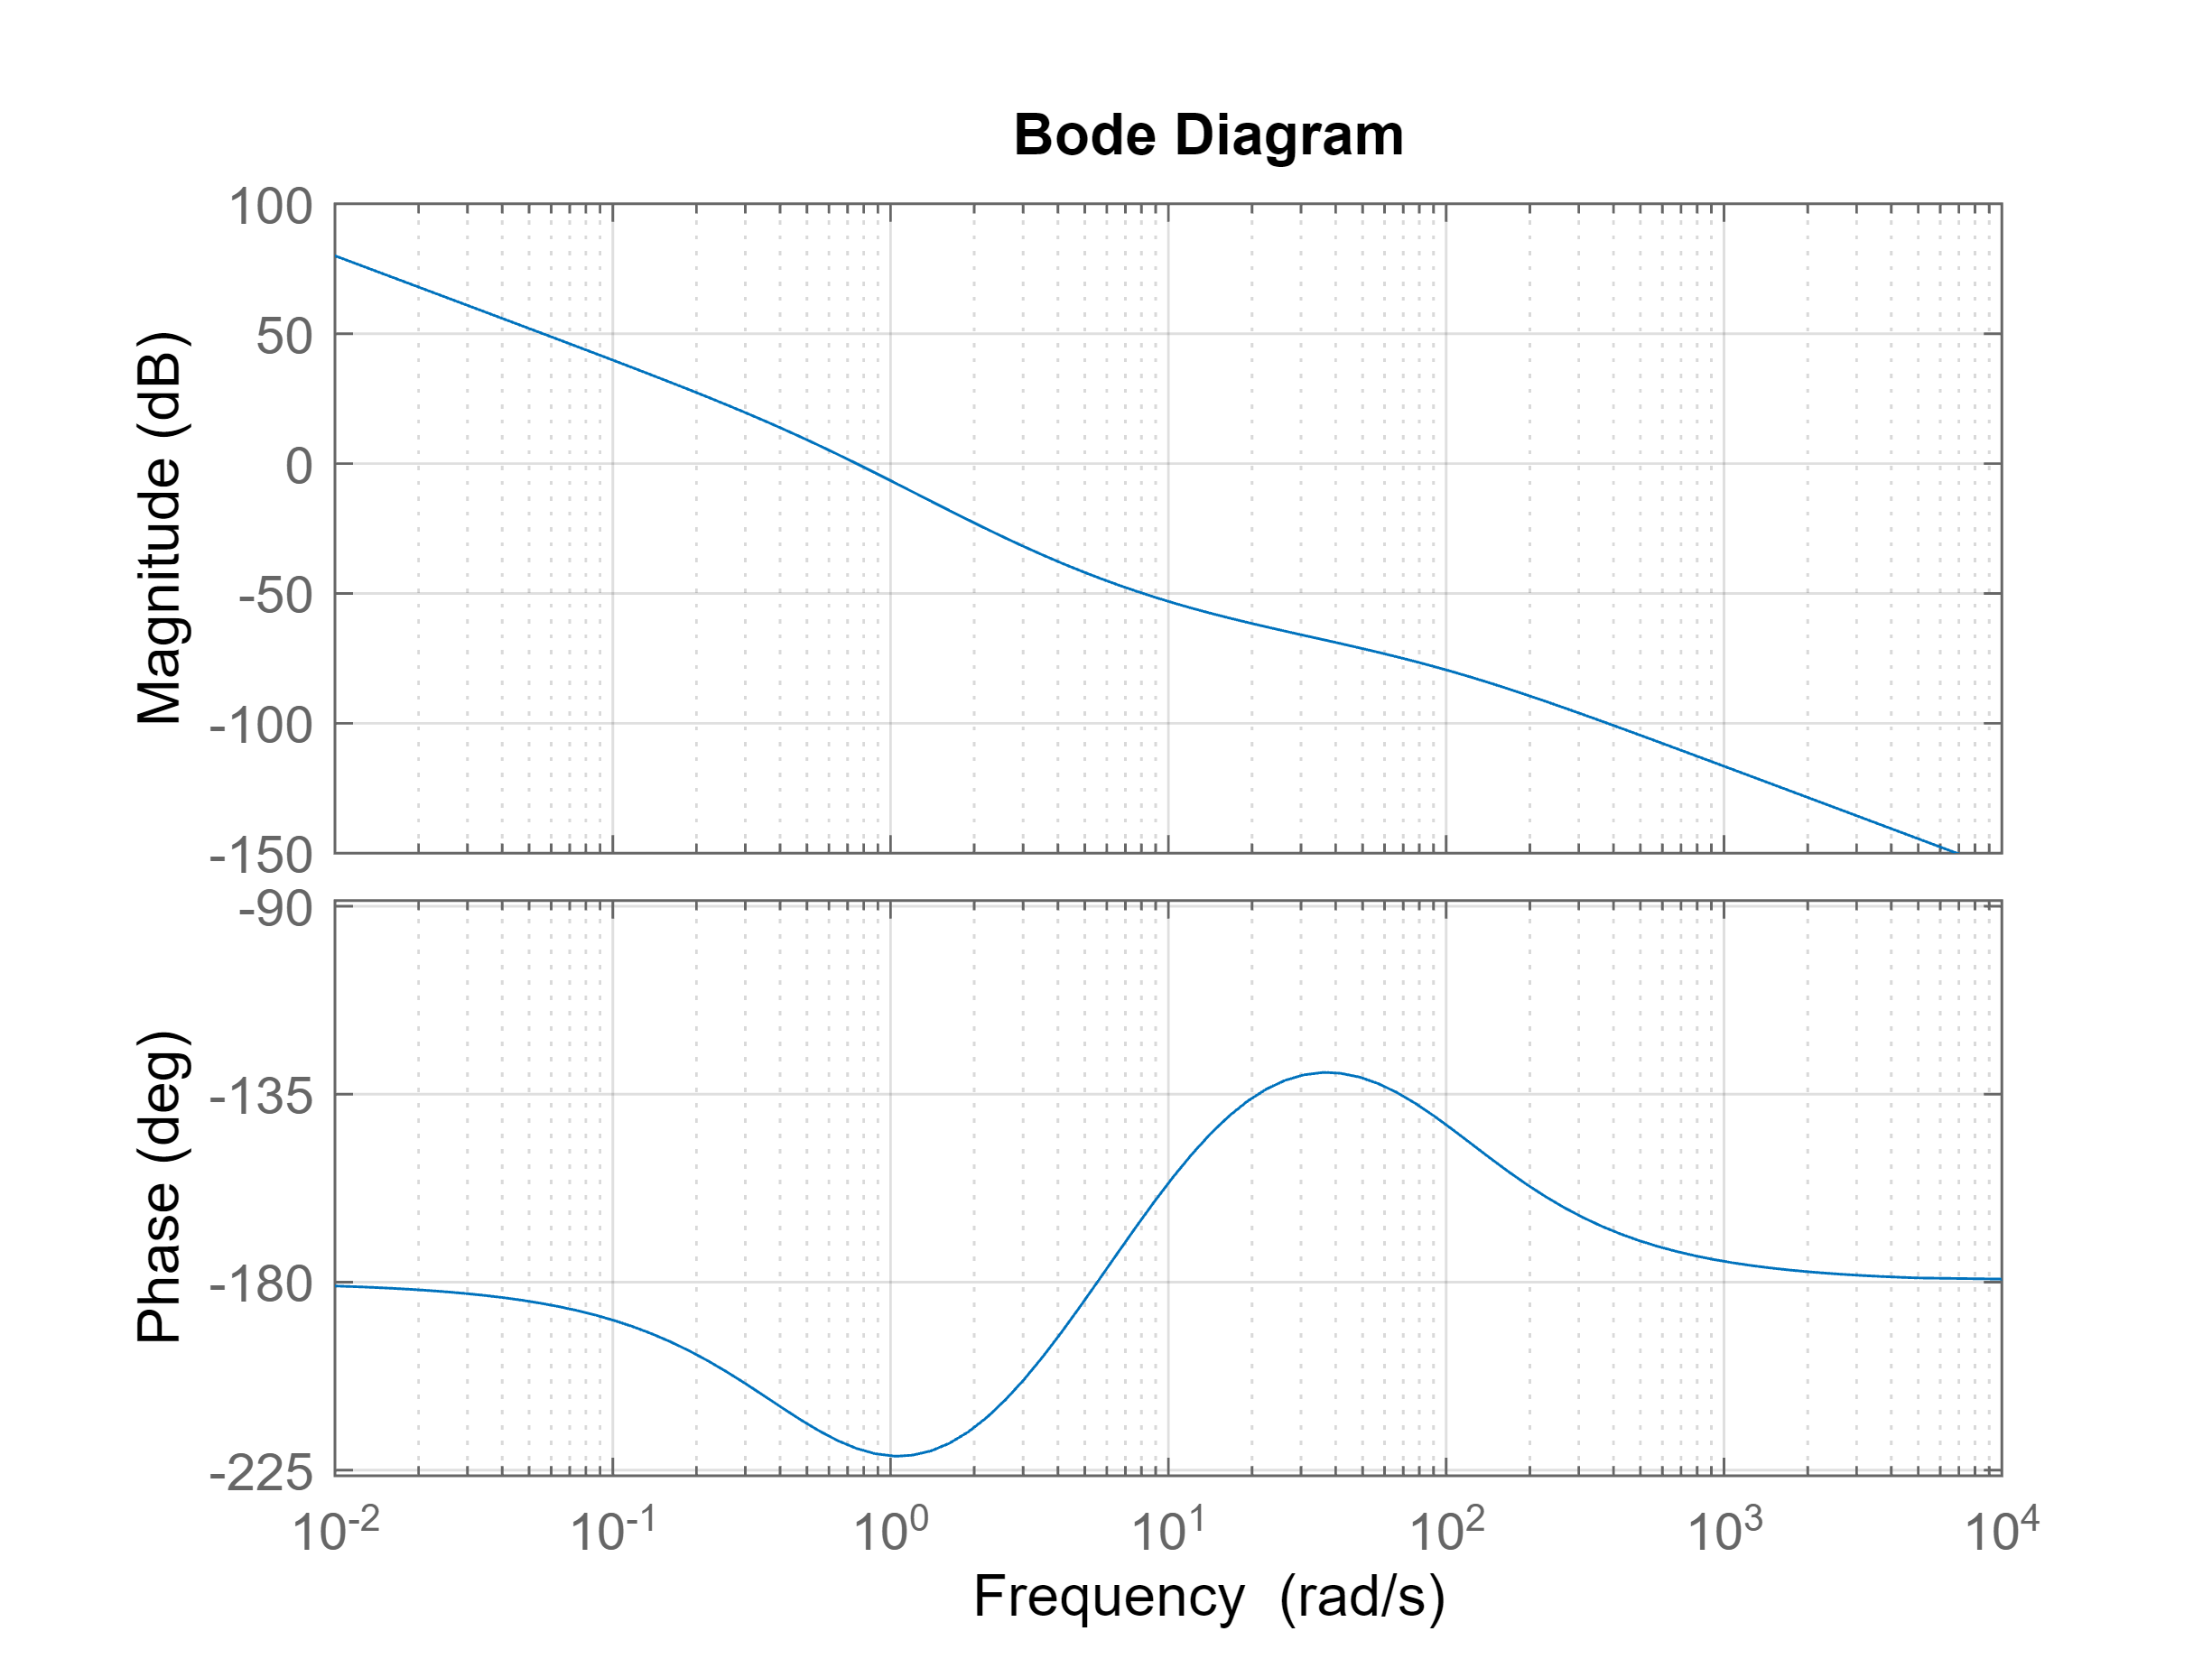

figure
bode(L), grid on

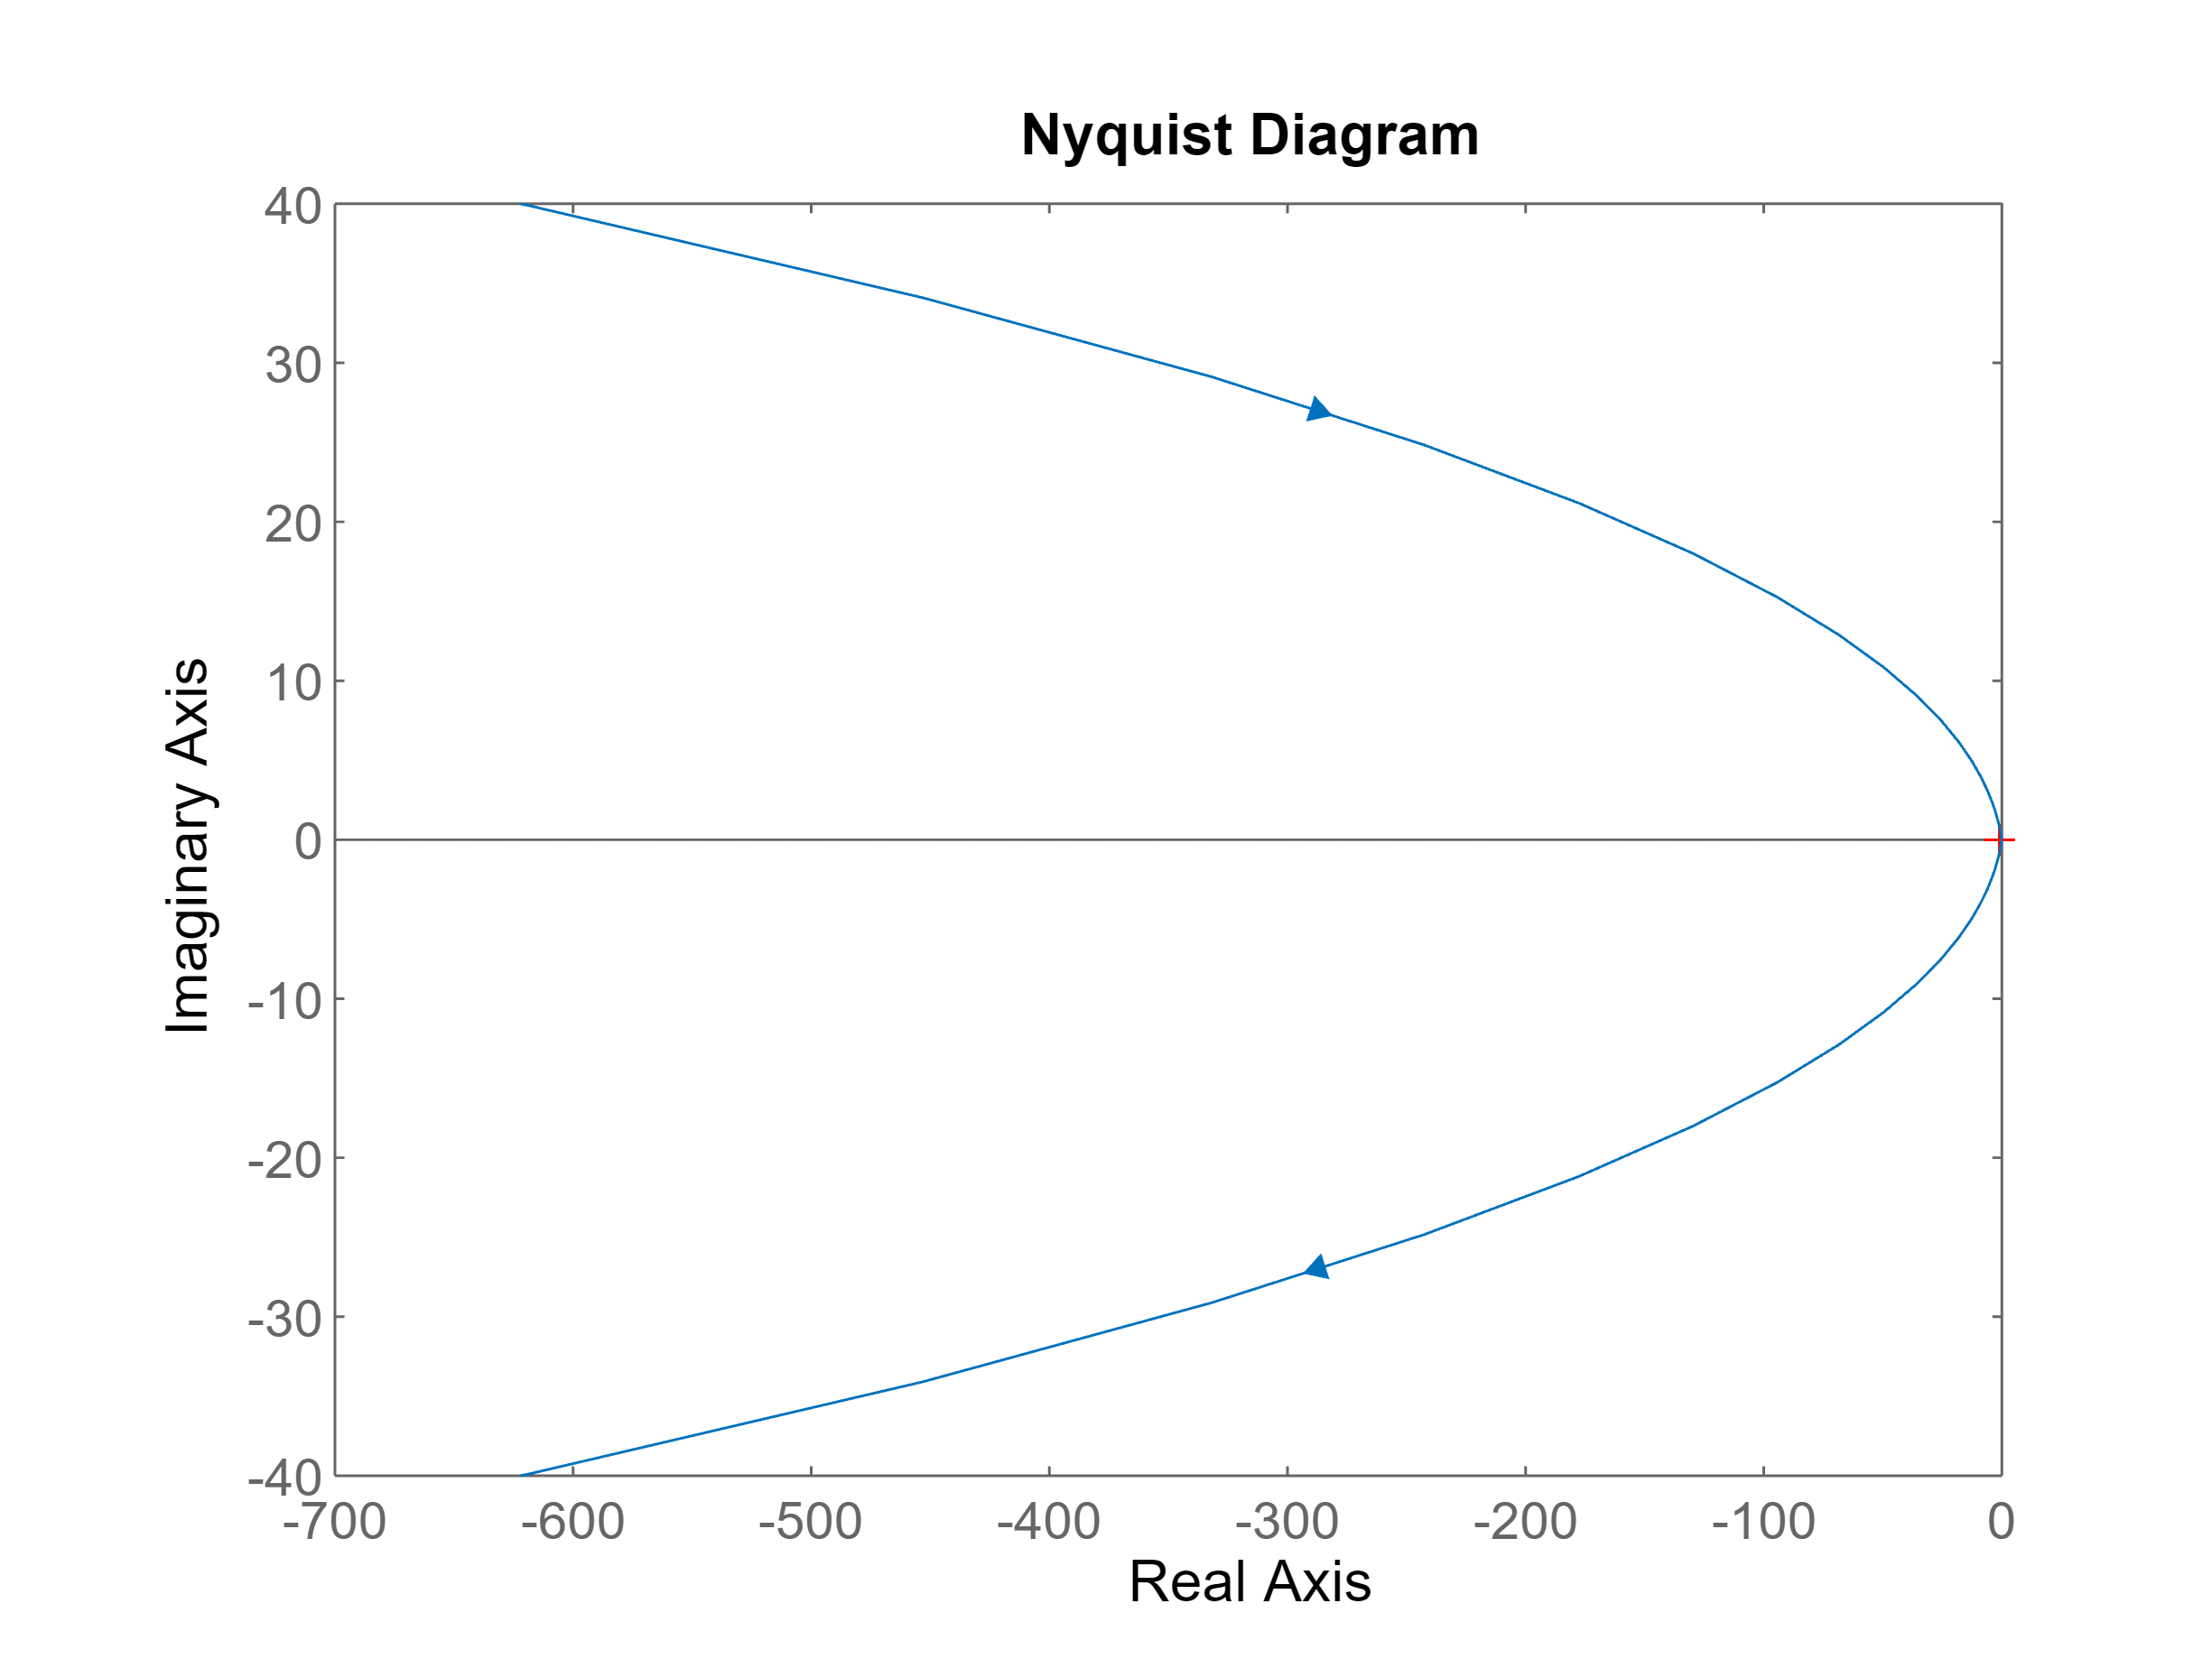

figure
nyquist(L)

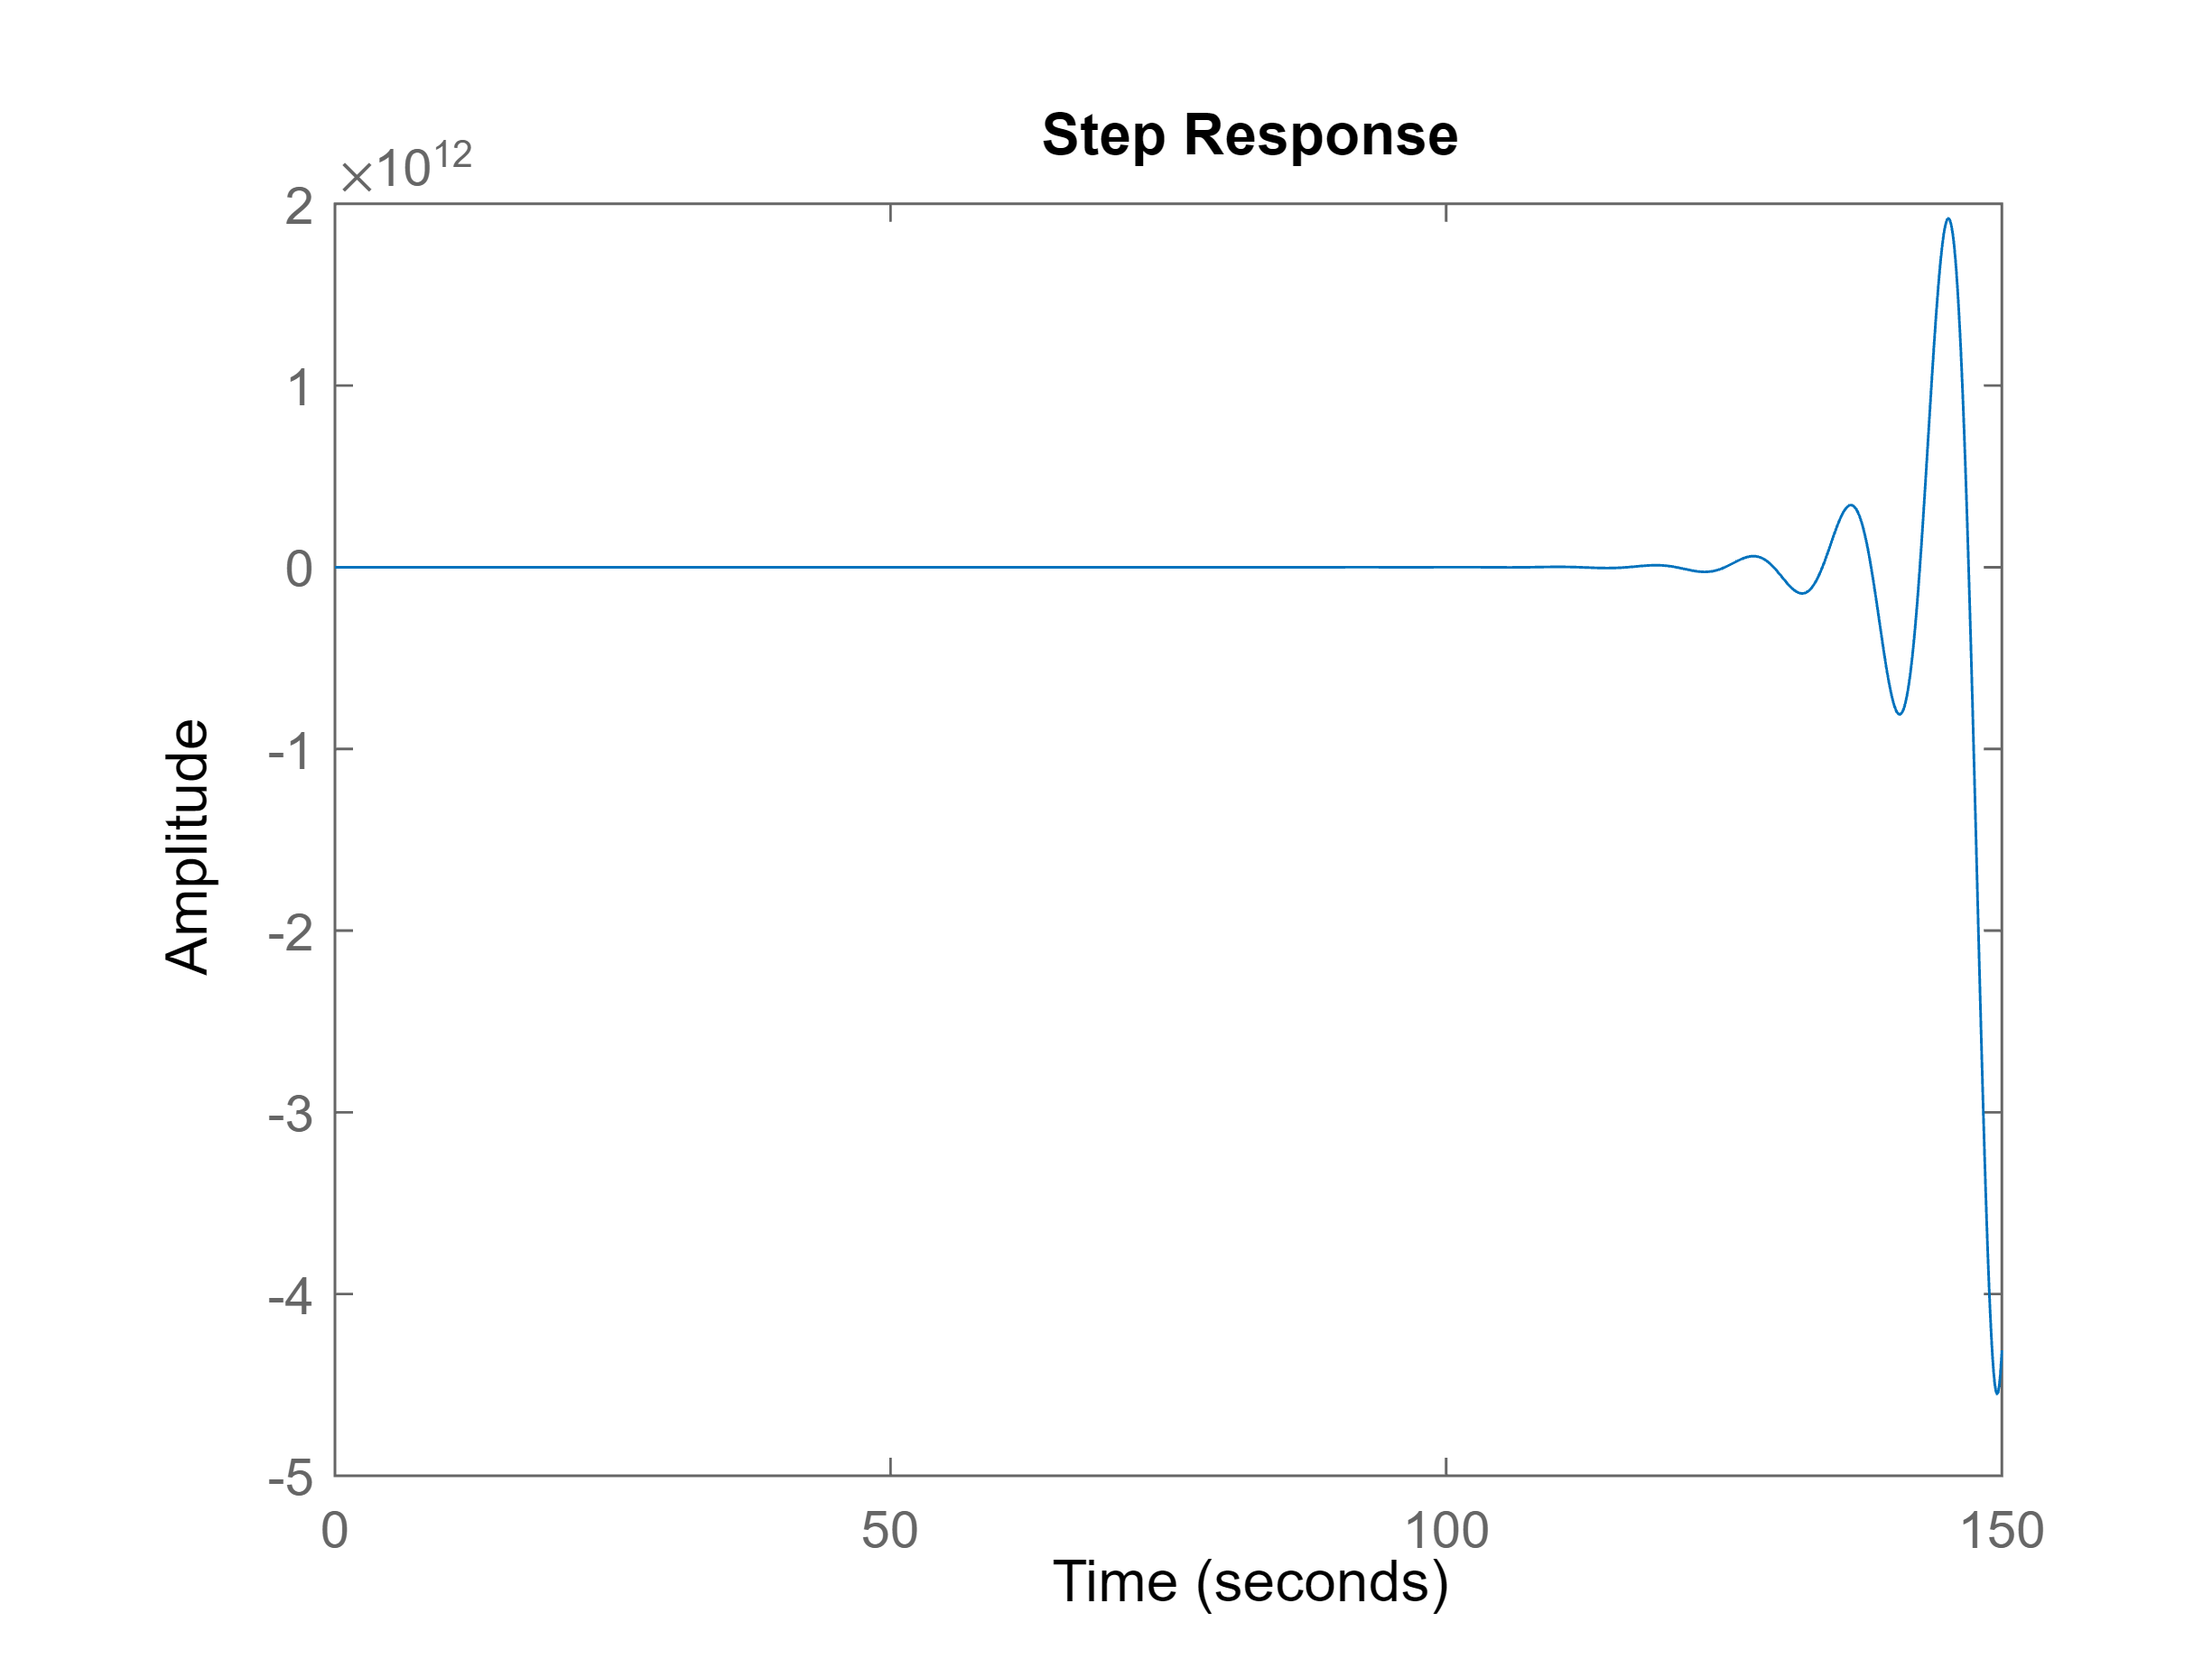

step(feedback(L,1))

## Intrinsic instability

Always closed-loop unstable.

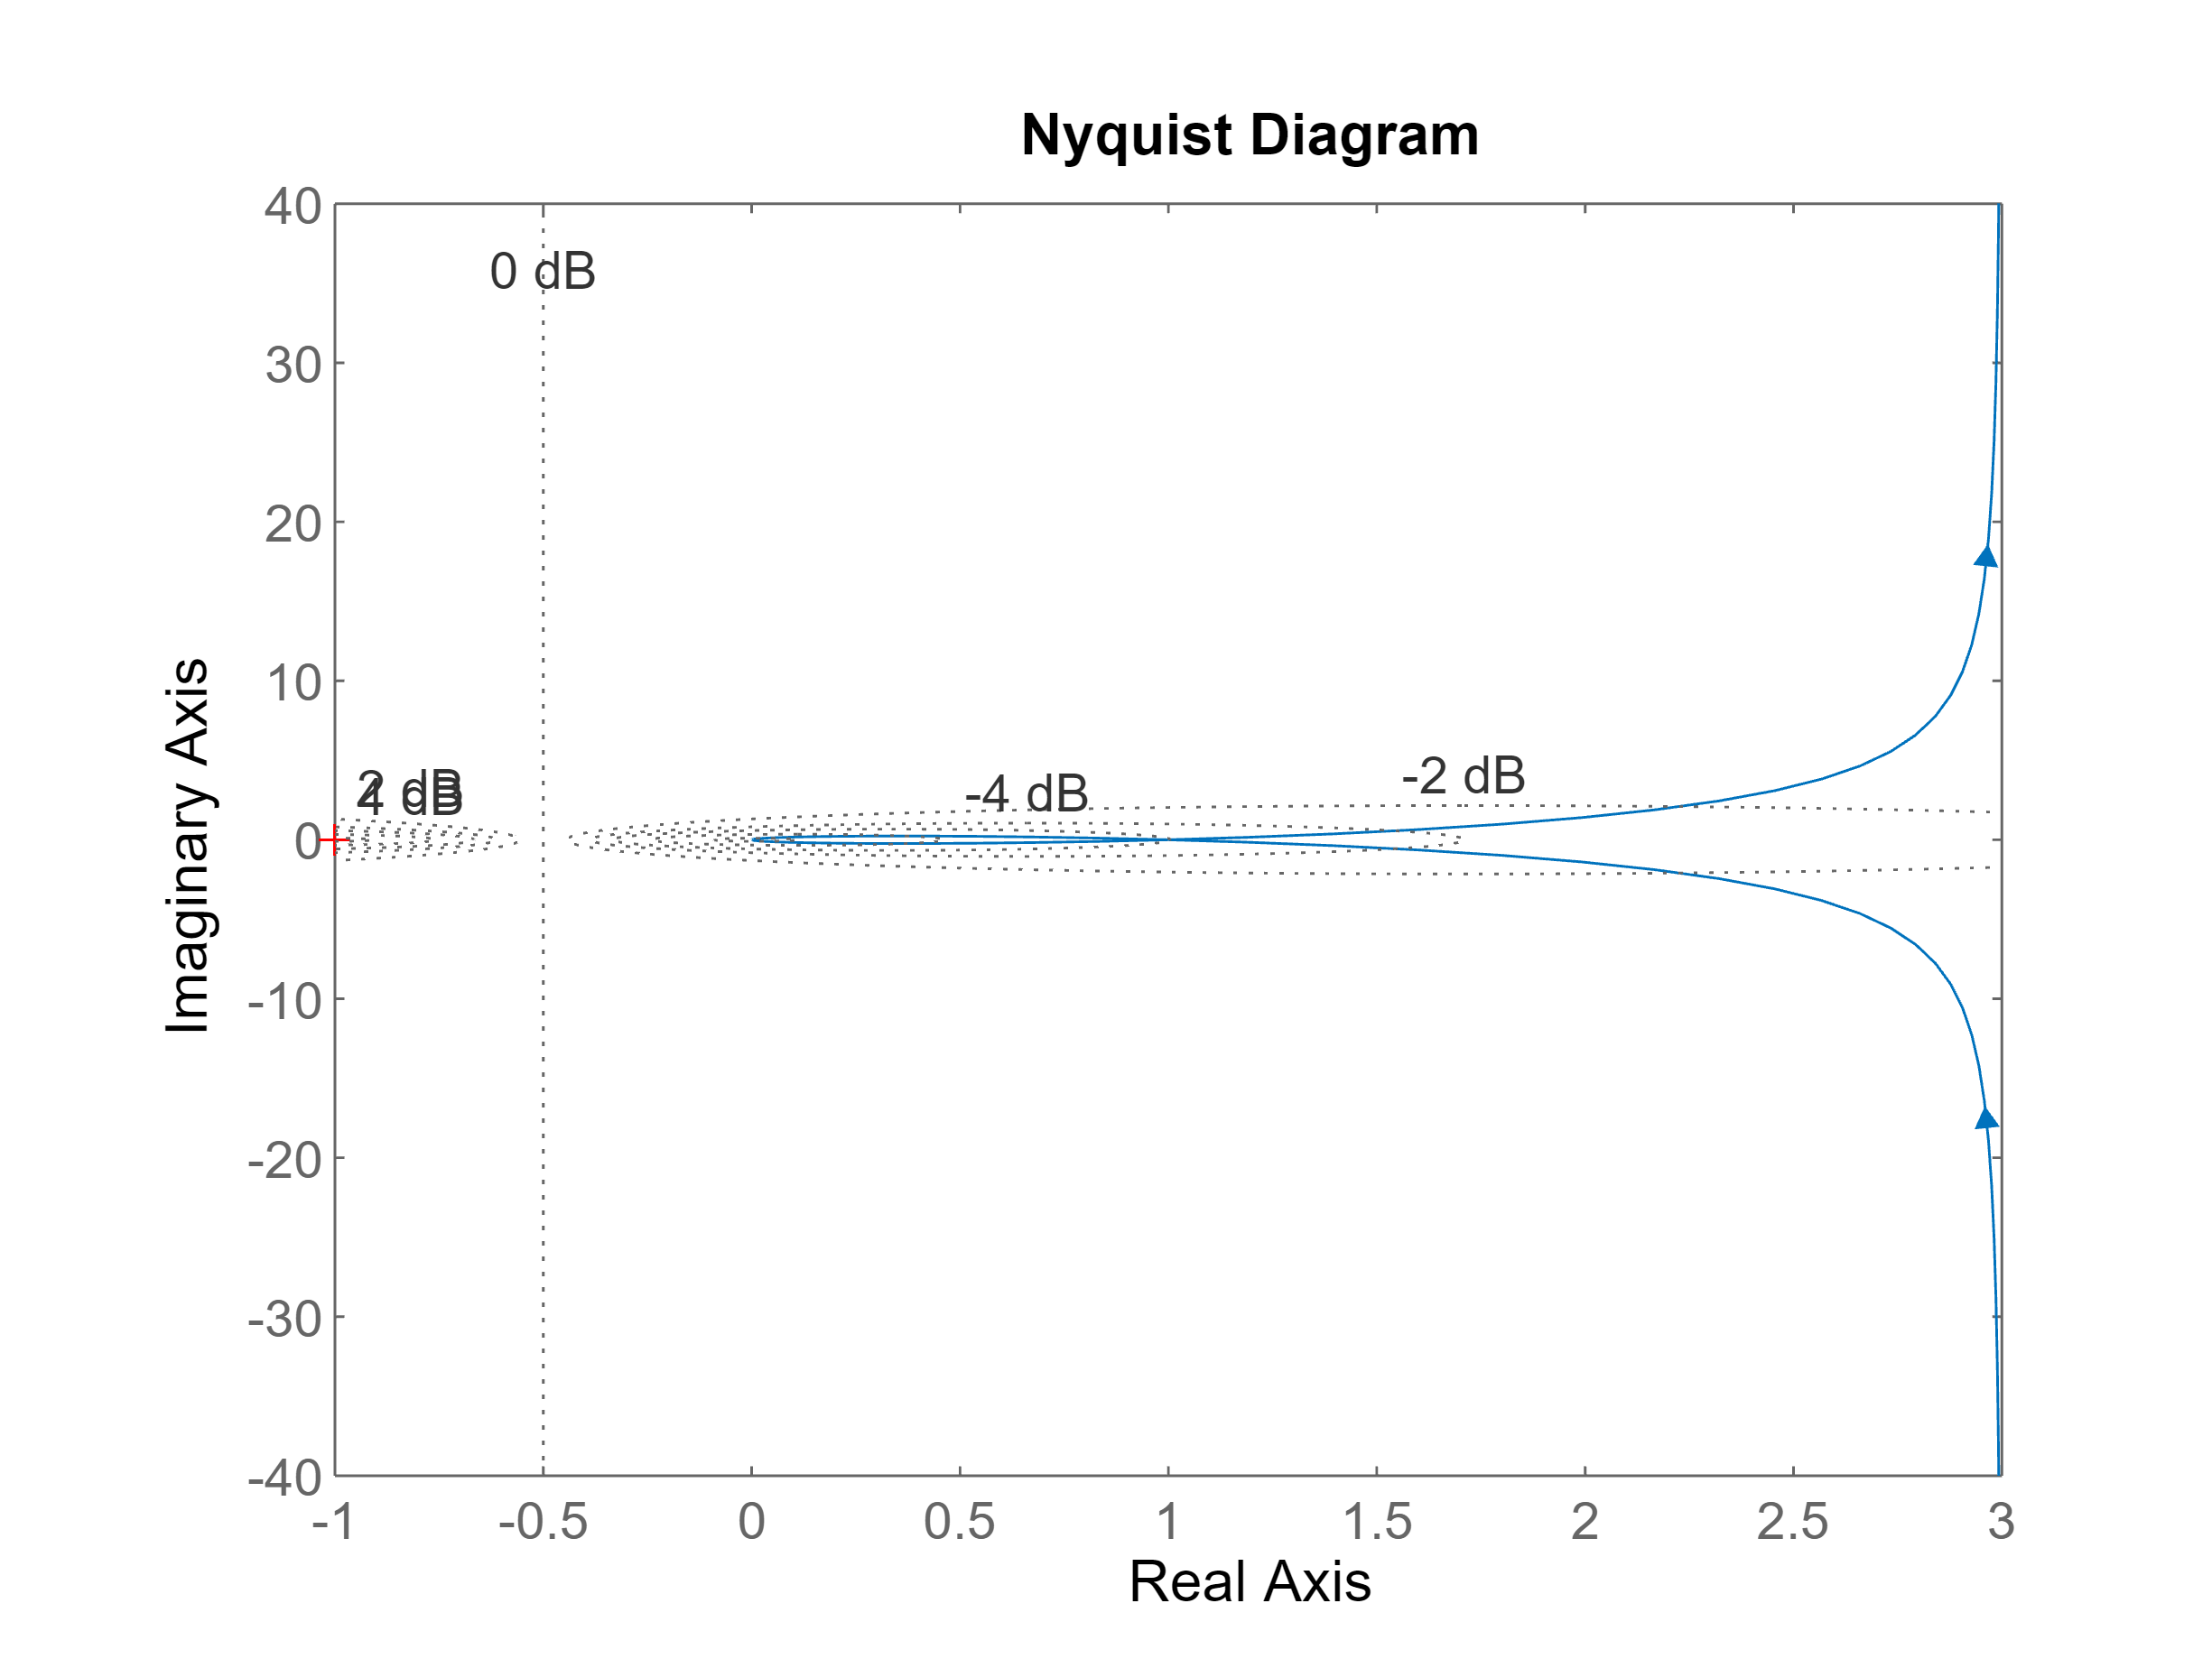

T0 = 1;
T1 = -2;

L = k*(1+s*T0)/(s*(1+s*T1));

figure
nyquist(L), grid on